# plotting tonotopic profiles, Tmem16a AC

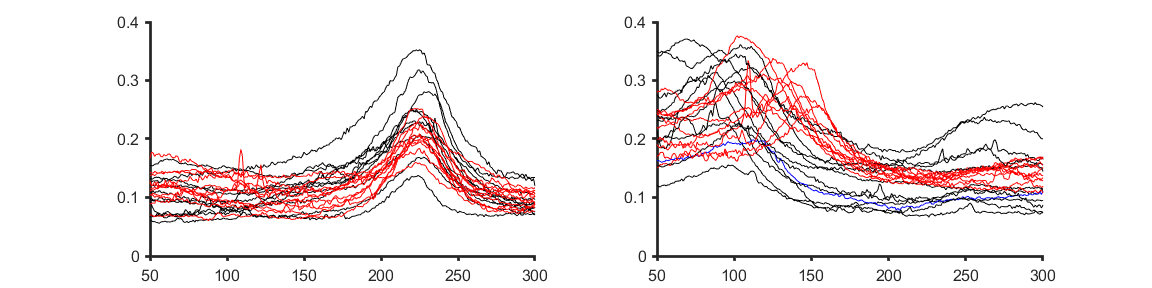

% load 20 dB profile (angles 37, 105)

% A1 upper axis
addpath('479_3 tecta flfl','479_4 flfl','474_1 tecta flfl','474_2 flfl','469_1 flfl','469_2 tecta flfl','383_1 flfl','405_1 tecta flfl','405_2 flfl','405_3 tecta flfl','405_5 tecta flfl','462_2 flfl','449_2 tecta flfl','485_1 flfl','485_2 tecta flfl','487_3 flfl','487_4 tecta flfl','491_1 tecta flfl','491_2 flfl','491_3 tecta flfl','494_2 flfl','494_3 tecta flfl','494_4 flfl')
con1 = load('479_4_20dBprofile3khz.mat'); %479_4 flfl, 5 tones, P15
con2 = load('474_2_20dBprofile3khz.mat'); %474_2 flfl, 5 tones, P15
con3 = load('469_1_20dBprofile3khz.mat'); %469_1 flfl, 5 tones, P14
con4 = load('383_1_20dBprofile3khz.mat'); %383_1 flfl, 16 tones, P14
con5 = load('405_2_20dBprofile3khz.mat'); %405_2, P16, 16 tones
con6 = load('462_2_20dBprofile3khz.mat'); % P17
con7 = load('485_1_20dBprofile3khz.mat'); % P15 
con8 = load('487_3_20dBprofile3khz.mat'); %P14, not center so requires shift
con9 = load('491_2_20dBprofile3khz.mat'); % P15
con10 = load('494_2_20dBprofile3khz.mat'); % P15
con11 = load('494_4_20dBprofile3khz.mat'); % P15
[con8_3max con8_3maxloc] = max(con8.meanAC1(1).profileraw);
diffcon8 = con8_3maxloc-225;
xcon8 = [-diffcon8+1:1:450-diffcon8];

tmem1 = load('479_3_20dBprofile3khz.mat'); % 479_3 tecta flfl, 5 tones
tmem2 = load('474_1_20dBprofile3khz.mat'); %474_1 tecta flfl, 5 tones
%tmem3 = load('469_2_20dBprofile3khz.mat'); %469_2 tecta flfl, 5 tones %poor
tmem4 = load('405_1_20dBprofile3khz.mat'); %405_1 tecta flfl, 16 tones
tmem5 = load('405_3_20dBprofile3khz.mat'); %405_3 tecta flfl, 16 tones
tmem6 = load('405_5_20dBprofile3khz.mat'); %405_5 tecta flfl, 16 tones
tmem7 = load('449_2_20dBprofile3khz.mat'); %449_2 tecta flfl, P17 - not center so requires shift
tmem8 = load('485_2_20dBprofile3khz.mat'); % P15
tmem9 = load('487_4_20dBprofile3khz.mat'); % P14
tmem10 = load('491_1_20dBprofile3khz1st.mat'); %P15, not center so requires shift
tmem11 = load('491_3_20dBprofile3khz.mat'); % P15
tmem12 = load('494_3_20dBprofile3khz.mat'); %P15
[tmem7_3max tmem7_3maxloc] = max(tmem7.meanAC1(1).profileraw);
difftmem7 = tmem7_3maxloc-225;
xtmem7 = [-difftmem7+1:1:450-difftmem7];

[tmem10_3max tmem10_3maxloc] = max(tmem10.meanAC1(1).profileraw);
difftmem10 = tmem10_3maxloc-225;
xtmem10 = [-difftmem10+1:1:450-difftmem10];

% show all traces
figure;
i = 1;
    subplot(1,2,i)
    plot(con1.meanAC1(i).profileraw','k')
    hold on
    plot(con2.meanAC1(i).profileraw','k')
    plot(con3.meanAC1(i).profileraw','k')
    plot(con4.meanAC1(i).profileraw','k')
    plot(con5.meanAC1(i).profileraw','k')
    plot(con6.meanAC1(i).profileraw','k')
    plot(con7.meanAC1(i).profileraw','k')
    plot(xcon8,con8.meanAC1(i).profileraw','k')
    plot(con9.meanAC1(i).profileraw','k')
    plot(con10.meanAC1(i).profileraw','k')
    plot(con11.meanAC1(i).profileraw','k')
    plot(tmem1.meanAC1(i).profileraw','r')
    plot(tmem2.meanAC1(i).profileraw','r')
    plot(tmem4.meanAC1(i).profileraw','r')
    plot(tmem5.meanAC1(i).profileraw','r')
    plot(tmem6.meanAC1(i).profileraw','r')
      plot(xtmem7,tmem7.meanAC1(i).profileraw','r')
    plot(tmem8.meanAC1(i).profileraw','r')
    plot(tmem9.meanAC1(i).profileraw','r')
    plot(xtmem10,tmem10.meanAC1(i).profileraw','r')
    plot(tmem11.meanAC1(i).profileraw','r')
    plot(tmem12.meanAC1(i).profileraw','r')
        xlim([50 300])
    ylim([0 0.4])
    figQuality(gcf,gca,[12 3])
    i = 5;
    subplot(1,2,2)
    plot(con1.meanAC1(i).profileraw','k')
    hold on
    plot(con2.meanAC1(i).profileraw','k')
    plot(con3.meanAC1(i).profileraw','k')
    plot(tmem1.meanAC1(i).profileraw','r')
   plot(tmem2.meanAC1(i).profileraw','r')
         plot(con7.meanAC1(i).profileraw','k')
     plot(xcon8,con8.meanAC1(i).profileraw','k')
     plot(con9.meanAC1(i).profileraw','k')
     plot(con10.meanAC1(i).profileraw','k')
     plot(con11.meanAC1(i).profileraw','k')
     plot(tmem8.meanAC1(i).profileraw','r')
    plot(tmem9.meanAC1(i).profileraw','r')
    plot(xtmem10,tmem10.meanAC1(i).profileraw','r')
    plot(tmem11.meanAC1(i).profileraw','r')
    plot(tmem12.meanAC1(i).profileraw','b')
    i = 13;
    plot(con4.meanAC1(i).profileraw','k')
    plot(con5.meanAC1(i).profileraw','k')
     plot(con6.meanAC1(i).profileraw','k')
    plot(tmem4.meanAC1(i).profileraw','r')
    plot(tmem5.meanAC1(i).profileraw','r')
    plot(tmem6.meanAC1(i).profileraw','r')
    plot(xtmem7,tmem7.meanAC1(i).profileraw','r')
        xlim([50 300])
    ylim([0 0.4])
    figQuality(gcf,gca,[12 3])

%figQuality(gcf,gca,[8 3])


% shift tmem7, con8, tmem10


tmem7.meanAC1(1).profileraw = [tmem7.meanAC1(1).profileraw(70:450);NaN(69,1)];
tmem7.meanAC1(13).profileraw = [tmem7.meanAC1(13).profileraw(70:450);NaN(69,1)];

tmem10.meanAC1(1).profileraw = [tmem10.meanAC1(1).profileraw(57:450);NaN(56,1)];
tmem10.meanAC1(5).profileraw = [tmem10.meanAC1(5).profileraw(57:450);NaN(56,1)];

con8.meanAC1(1).profileraw = [con8.meanAC1(1).profileraw(20:450);NaN(19,1)];
con8.meanAC1(5).profileraw = [con8.meanAC1(5).profileraw(20:450);NaN(19,1)];

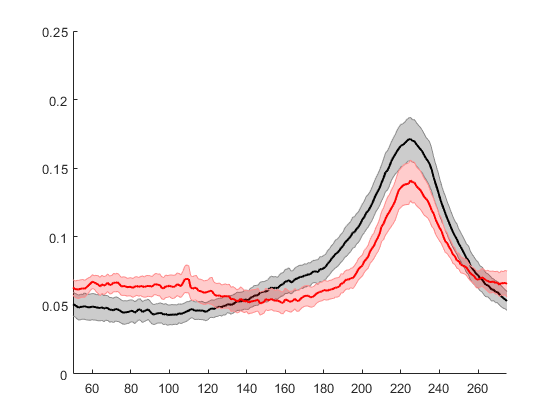


% generate means
i = 1;
con3kHz = nanmean([con1.meanAC1(i).profileraw';con2.meanAC1(i).profileraw';con3.meanAC1(i).profileraw';con5.meanAC1(i).profileraw';con6.meanAC1(i).profileraw';con7.meanAC1(i).profileraw';con8.meanAC1(i).profileraw';con9.meanAC1(i).profileraw';con10.meanAC1(i).profileraw';con11.meanAC1(i).profileraw';],1)-0.05;
tmem3kHz = nanmean([tmem1.meanAC1(i).profileraw';tmem2.meanAC1(i).profileraw';tmem4.meanAC1(i).profileraw';tmem5.meanAC1(i).profileraw';tmem6.meanAC1(i).profileraw';tmem7.meanAC1(i).profileraw';tmem8.meanAC1(i).profileraw';tmem9.meanAC1(i).profileraw';tmem10.meanAC1(i).profileraw';tmem11.meanAC1(i).profileraw';tmem12.meanAC1(i).profileraw';],1)-0.05;
con48kHz = nanmean([con1.meanAC1(5).profileraw';con2.meanAC1(5).profileraw';con3.meanAC1(5).profileraw';con5.meanAC1(13).profileraw';con6.meanAC1(13).profileraw';con7.meanAC1(5).profileraw';con8.meanAC1(5).profileraw';con9.meanAC1(5).profileraw';con10.meanAC1(5).profileraw';con11.meanAC1(5).profileraw';],1)-0.05;
tmem48kHz = nanmean([tmem1.meanAC1(5).profileraw';tmem2.meanAC1(5).profileraw';tmem4.meanAC1(13).profileraw';tmem5.meanAC1(13).profileraw';tmem6.meanAC1(13).profileraw';tmem7.meanAC1(13).profileraw';tmem8.meanAC1(5).profileraw';tmem9.meanAC1(5).profileraw';tmem10.meanAC1(5).profileraw';tmem11.meanAC1(5).profileraw';tmem12.meanAC1(5).profileraw';],1)-0.05;

con3kHzstd = nanstd([con1.meanAC1(i).profileraw';con2.meanAC1(i).profileraw';con3.meanAC1(i).profileraw';con5.meanAC1(i).profileraw';con6.meanAC1(i).profileraw';con7.meanAC1(i).profileraw';con8.meanAC1(i).profileraw';con9.meanAC1(i).profileraw';con10.meanAC1(i).profileraw';con11.meanAC1(i).profileraw';],1)/sqrt(11);
tmem3kHzstd = nanstd([tmem1.meanAC1(i).profileraw';tmem2.meanAC1(i).profileraw';tmem4.meanAC1(i).profileraw';tmem5.meanAC1(i).profileraw';tmem6.meanAC1(i).profileraw';tmem7.meanAC1(i).profileraw';tmem8.meanAC1(i).profileraw';tmem9.meanAC1(i).profileraw';tmem10.meanAC1(i).profileraw';tmem11.meanAC1(i).profileraw';tmem12.meanAC1(i).profileraw';],1)/sqrt(11);
con48kHzstd = nanstd([con1.meanAC1(5).profileraw';con2.meanAC1(5).profileraw';con3.meanAC1(5).profileraw';con5.meanAC1(13).profileraw';con6.meanAC1(13).profileraw';con7.meanAC1(5).profileraw';con8.meanAC1(5).profileraw';con9.meanAC1(5).profileraw';con10.meanAC1(5).profileraw';con11.meanAC1(5).profileraw';],1)/sqrt(11);
tmem48kHzstd = nanstd([tmem1.meanAC1(5).profileraw';tmem2.meanAC1(5).profileraw';tmem4.meanAC1(13).profileraw';tmem5.meanAC1(13).profileraw';tmem6.meanAC1(13).profileraw';tmem7.meanAC1(13).profileraw';tmem8.meanAC1(5).profileraw';tmem9.meanAC1(5).profileraw';tmem10.meanAC1(5).profileraw';tmem11.meanAC1(5).profileraw';tmem12.meanAC1(5).profileraw';],1)/sqrt(11);
% plot mean profiles
x = [1:1:450];
figure;
    c1 = shadedErrorBar(x,con3kHz,con3kHzstd);
    c1.mainLine.LineWidth = 1.5;
    hold on
    c1 = shadedErrorBar(x,tmem3kHz,tmem3kHzstd,'lineprops','r');
    c1.mainLine.LineWidth = 1.5;
    xlim([50 275]) 
    ylim([0 0.25])

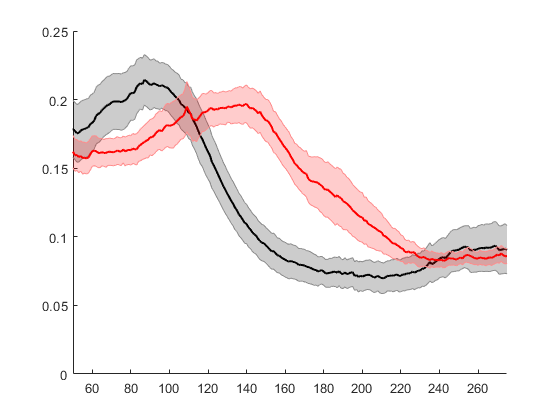

x = [1:1:450];
figure;
    c1 = shadedErrorBar(x,con48kHz,con48kHzstd);
    c1.mainLine.LineWidth = 1.5;
    hold on
    c1 = shadedErrorBar(x,tmem48kHz,tmem48kHzstd,'lineprops','r');
    c1.mainLine.LineWidth = 1.5;
xlim([50 275])    
    ylim([0 0.25])


% plot raw    
figure
subplot(1,3,1)
 c1 = shadedErrorBar(x,con3kHz,con3kHzstd);
 c1.mainLine.LineWidth = 1.5;
 hold on
 [y1_1 x1_1] = nanmax(smooth(con3kHz(50:300)));
 l1_1 = line([x1_1+49 x1_1+49],[0,y1_1]);
 l1_1.Color = 'k';
 l1_1.LineStyle = ':';
 l1_1.LineWidth = 1;
 c1 = shadedErrorBar(x,tmem3kHz,tmem3kHzstd,'lineprops','r');
 c1.mainLine.LineWidth = 1.5;
 [y2_1 x2_1] = nanmax(smooth(tmem3kHz(50:300)))

y2_1 = 0.1395

x2_1 = 176

 l2_1 = line([x2_1+49 x2_1+49],[0,y2_1]);
 l2_1.Color = 'r';
 l2_1.LineStyle = ':';
 l2_1.LineWidth = 1;
  ylim([0 0.25])
 xlim([50 275])
 figQuality(gcf,gca,[4 1])
 
 subplot(1,3,2)
 c1 = shadedErrorBar(x,con48kHz,con48kHzstd);
 c1.mainLine.LineWidth = 1.5;
 [y1_2 x1_2] = nanmax(smooth(con48kHz(50:300)));
 l1_2 = line([x1_2+49 x1_2+49],[0,y1_2]);
 l1_2.Color = 'k';
 l1_2.LineStyle = ':'

l1_2 =   Line with properties:

              Color: [0 0 0]
          LineStyle: ':'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [87 87]
              YData: [0 0.2126]
              ZData: [1×0 double]

  Show all properties


 l1_2.LineWidth = 1;
 c1 = shadedErrorBar(x,tmem48kHz,tmem48kHzstd,'lineprops','r');
 c1.mainLine.LineWidth = 1.5;
 [y2_2 x2_2] = nanmax(smooth(tmem48kHz(50:300)));
 l2_2 = line([x2_2+49 x2_2+49],[0,y2_2]);
 l2_2.Color = 'r';
 l2_2.LineStyle = ':';
 l2_2.LineWidth = 1;
 patch([x1_2+50 x1_2+50 x2_2+49 x2_2+49], [0 y1_2 y1_2 0],'k','EdgeColor','none','FaceAlpha',0.1);
  ylim([0 0.25])
 xlim([50 275])
  figQuality(gcf,gca,[4 1])
  
  subplot(1,3,3)
 c1 = shadedErrorBar(x,con3kHz,con3kHzstd);
 c1.mainLine.LineWidth = 1.5;
 hold on
 [y1_1 x1_1] = nanmax(smooth(con3kHz(50:300)));
 l1_1 = line([x1_1+49 x1_1+49],[0,y1_1]);
 l1_1.Color = 'k';
 l1_1.LineStyle = ':';
 l1_1.LineWidth = 1;
 c1 = shadedErrorBar(x,tmem3kHz,tmem3kHzstd,'lineprops','r');
 c1.mainLine.LineWidth = 1.5;
 [y2_1 x2_1] = nanmax(smooth(tmem3kHz(50:300)))

y2_1 = 0.1395

x2_1 = 176

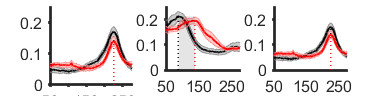

 l2_1 = line([x2_1+49 x2_1+49],[0,y2_1]);
 l2_1.Color = 'r';
 l2_1.LineStyle = ':';
 l2_1.LineWidth = 1;
  ylim([0 0.25])
 xlim([50 275])
 figQuality(gcf,gca,[4 1])

 %print(gcf,'-dpdf')

  % overlap 3-48 kHz 
 figure
subplot(1,2,1)
 c1 = shadedErrorBar(x,tmem3kHz,tmem3kHzstd,'lineprops','r');
 c1.mainLine.LineWidth = 1.5;
 hold on
 [y1_1 x1_1] = nanmax(smooth(tmem3kHz(50:300)));
 l1_1 = line([x1_1+49 x1_1+49],[0,y1_1]);
 l1_1.Color = 'r';
 l1_1.LineStyle = ':';
 l1_1.LineWidth = 1;
 c1 = shadedErrorBar(x,tmem48kHz,tmem48kHzstd,'lineprops','r');
 c1.mainLine.LineWidth = 1.5;
 [y2_1 x2_1] = nanmax(smooth(tmem48kHz(50:300)))

y2_1 = 0.1962

x2_1 = 89

 l2_1 = line([x2_1+49 x2_1+49],[0,y2_1]);
 l2_1.Color = 'r';
 l2_1.LineStyle = ':';
 l2_1.LineWidth = 1;
  patch([x1_1+49 x1_1+49 x2_1+49 x2_1+49], [0 y1_2 y1_2 0],'r','EdgeColor','none','FaceAlpha',0.1);
  ylim([0 0.25])
 xlim([50 275])
 figQuality(gcf,gca,[3 1]) 
  
  subplot(1,2,2)
 c1 = shadedErrorBar(x,con3kHz,con3kHzstd);
 c1.mainLine.LineWidth = 1.5;
 [y1_2 x1_2] = nanmax(smooth(con3kHz(50:300)));
 l1_2 = line([x1_2+49 x1_2+49],[0,y1_2]);
 l1_2.Color = 'k';
 l1_2.LineStyle = ':'

l1_2 =   Line with properties:

              Color: [0 0 0]
          LineStyle: ':'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [225 225]
              YData: [0 0.1703]
              ZData: [1×0 double]

  Show all properties


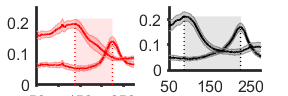

 l1_2.LineWidth = 1;
 c1 = shadedErrorBar(x,con48kHz,con48kHzstd,'lineprops','k');
 c1.mainLine.LineWidth = 1.5;
 [y2_2 x2_2] = nanmax(smooth(con48kHz(50:300)));
 l2_2 = line([x2_2+49 x2_2+49],[0,y2_2]);
 l2_2.Color = 'k';
 l2_2.LineStyle = ':';
 l2_2.LineWidth = 1;
 patch([x1_2+50 x1_2+50 x2_2+49 x2_2+49], [0 y2_2 y2_2 0],'k','EdgeColor','none','FaceAlpha',0.1);
  ylim([0 0.25])
 xlim([50 275])
  figQuality(gcf,gca,[3 1])

  %print(gcf,'-dpdf')

  
  

% plot normalized 
    figure
    subplot(1,3,1)
    plot(tmem3kHz/max(tmem3kHz(50:300)),'r')
    [y1_1 x1_1] = nanmax(smooth(con3kHz(50:300)));
    hold on
     l1_1 = line([x1_1+49 x1_1+49],[0,1]);
 l1_1.Color = 'r';
 l1_1.LineStyle = ':';
 l1_1.LineWidth = 1;
    plot(tmem48kHz/max(tmem48kHz(50:300)),'r')
     [y2_1 x2_1] = nanmax(smooth(tmem48kHz(50:300)))

y2_1 = 0.1962

x2_1 = 89

 l2_1 = line([x2_1+49 x2_1+49],[0,1]);
 l2_1.Color = 'r';
 l2_1.LineStyle = ':';
 l2_1.LineWidth = 1;
  ylim([0 1])
 xlim([50 300])
 patch([x1_1+49 x1_1+49 x2_1+49 x2_1+49], [0 1 1 0],'r','EdgeColor','none','FaceAlpha',0.1);
  figQuality(gcf,gca,[4 1])

subplot(1,3,2)
    plot(con3kHz/max(con3kHz(50:300)),'k')
    [y1_1 x1_1] = nanmax(smooth(con3kHz(50:300)));
    hold on
     l1_1 = line([x1_1+49 x1_1+49],[0,1]);
 l1_1.Color = 'k';
 l1_1.LineStyle = ':';
 l1_1.LineWidth = 1;
    plot(con48kHz/max(con48kHz(50:300)),'k')
     [y2_1 x2_1] = nanmax(smooth(con48kHz(50:300)))

y2_1 = 0.2126

x2_1 = 38

 l2_1 = line([x2_1+49 x2_1+49],[0,1]);
 l2_1.Color = 'k';
 l2_1.LineStyle = ':';
 l2_1.LineWidth = 1;
  ylim([0 1])
 xlim([50 300])
   patch([x1_1+50 x1_1+50 x2_1+49 x2_1+49], [0 1 1 0],'k','EdgeColor','none','FaceAlpha',0.1);
  figQuality(gcf,gca,[4 1])
 
    subplot(1,3,3)
    plot(tmem3kHz/max(tmem3kHz(50:300)),'r')
    [y1_1 x1_1] = nanmax(smooth(con3kHz(50:300)));
    hold on
     l1_1 = line([x1_1+49 x1_1+49],[0,1]);
 l1_1.Color = 'r';
 l1_1.LineStyle = ':';
 l1_1.LineWidth = 1;
    plot(tmem48kHz/max(tmem48kHz(50:300)),'r')
     [y2_1 x2_1] = nanmax(smooth(tmem48kHz(50:300)))

y2_1 = 0.1962

x2_1 = 89

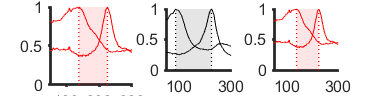

 l2_1 = line([x2_1+49 x2_1+49],[0,1]);
 l2_1.Color = 'r';
 l2_1.LineStyle = ':';
 l2_1.LineWidth = 1;
  ylim([0 1])
 xlim([50 300])
 patch([x1_1+49 x1_1+49 x2_1+49 x2_1+49], [0 1 1 0],'r','EdgeColor','none','FaceAlpha',0.1);
  figQuality(gcf,gca,[4 1])

 % print(gcf,'-dpdf')


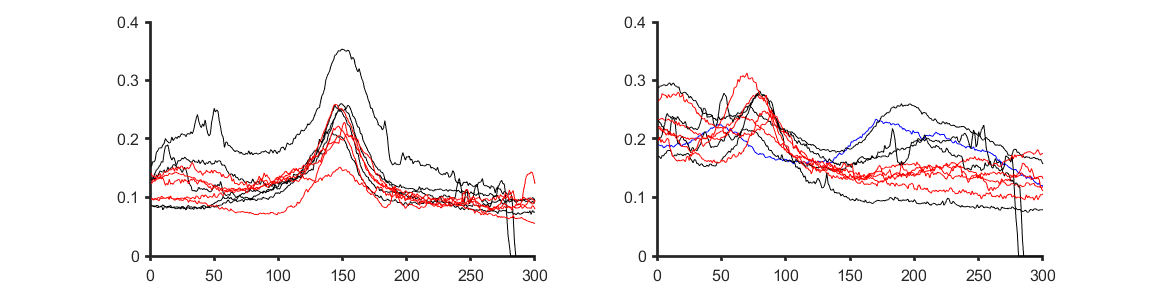

  
 % plot A1 - lower axis - appears to be less obvious? but also noisier
 % show all traces
figure;
i = 1;
    subplot(1,2,i)
    plot(con1.meanAC2(i).profileraw','k')
    hold on
    plot(con2.meanAC2(i).profileraw','k')
    plot(con3.meanAC2(i).profileraw','k')
    plot(con4.meanAC2(i).profileraw','k')
    plot(con5.meanAC2(i).profileraw','k')
    plot(tmem1.meanAC2(i).profileraw','r')
    plot(tmem2.meanAC2(i).profileraw','r')
    plot(tmem4.meanAC2(i).profileraw','r')
    plot(tmem5.meanAC2(i).profileraw','r')
    plot(tmem6.meanAC2(i).profileraw','r')
        xlim([0 300])
    ylim([0 0.4])
    figQuality(gcf,gca,[12 3])
    i = 5;
    subplot(1,2,2)
    plot(con1.meanAC2(i).profileraw','k')
    hold on
    plot(con2.meanAC2(i).profileraw','k')
    plot(con3.meanAC2(i).profileraw','k')
    plot(tmem1.meanAC2(i).profileraw','r')
    plot(tmem2.meanAC2(i).profileraw','r')
    i = 13;
    plot(con4.meanAC2(i).profileraw','k')
    plot(con5.meanAC2(i).profileraw','k')
    plot(tmem4.meanAC2(i).profileraw','r')
    plot(tmem5.meanAC2(i).profileraw','r')
    plot(tmem6.meanAC2(i).profileraw','r')
        xlim([0 300])
    ylim([0 0.4])
    figQuality(gcf,gca,[12 3])

%figQuality(gcf,gca,[8 3])
 

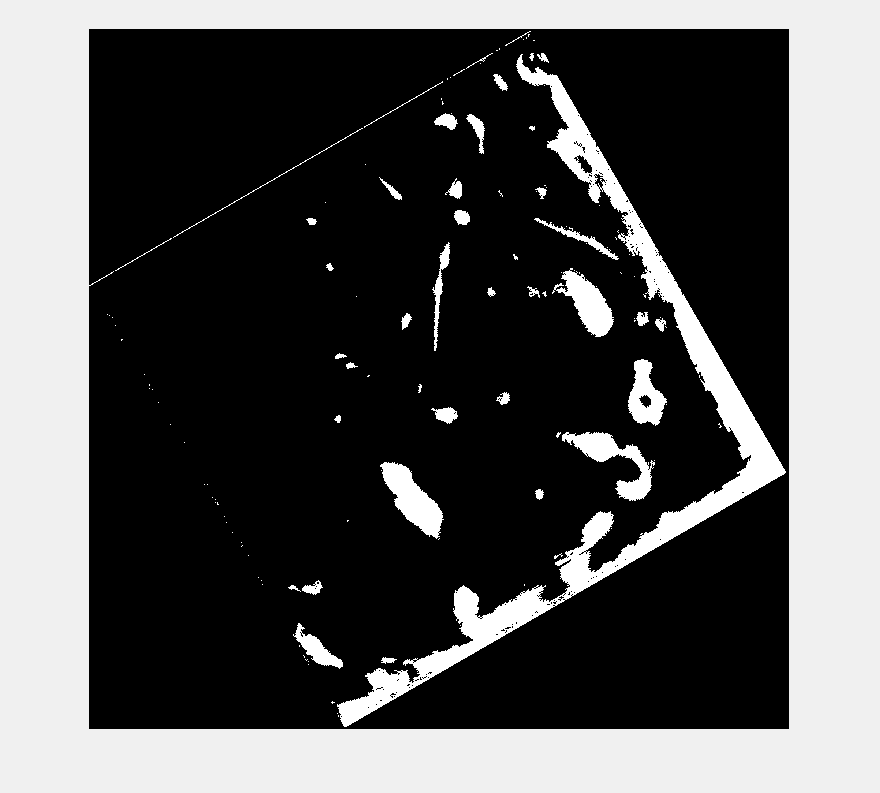

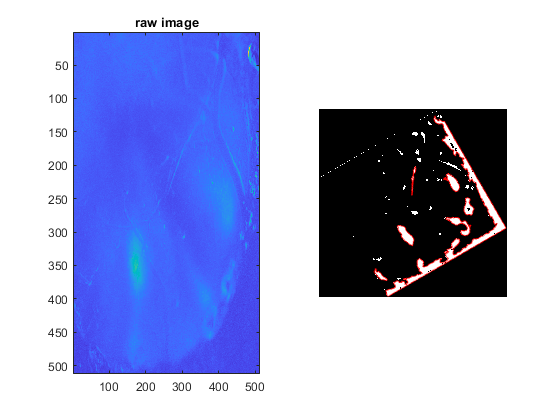

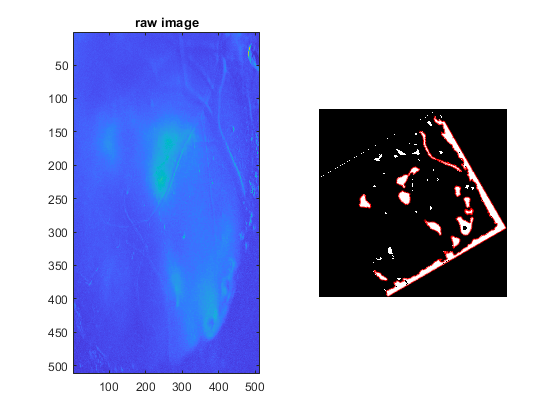


% generate control maps + mean map

%con6 = getACmaps(con6); %462_2
%con1 = getACmaps(con1); %479_4
%con2 = getACmaps(con2); %474_2
%con3 = getACmaps(con3); %469_1
%con5 = getACmaps(con5); % 405_2
% con7 = getACmaps(con7); % 485_1
% con8 = getACmaps(con8); %487_3
% con9 = getACmaps(con9); %491_2
%con10 = getACmaps(con10); %494_2

%con11 = getACmaps(con11); %494_4
% save (['487_3_20dBmap.mat'],'con8')


figure
hold on
boundptsx = [];
boundptsy = [];
for x = 2:con6(1).numbounds3 
    hold on
    plot(con6(x).boundary3(:,2)-con6(1).centroid(1,1),con6(x).boundary3(:,1)-con6(1).centroid(1,2),'c','LineWidth', 1)
        boundptsx = [boundptsx,(con6(x).boundary3(:,2)-con6(1).centroid(1,1))'];
    boundptsy = [boundptsy,(con6(x).boundary3(:,1)-con6(1).centroid(1,2))'];
end
    
for x = 4:con6(1).numbounds48 
    plot(con6(x).boundary48(:,2)-con6(1).centroid(1,1),con6(x).boundary48(:,1)-con6(1).centroid(1,2),'r','LineWidth', 1)
     boundptsx = [boundptsx,(con6(x).boundary48(:,2)-con6(1).centroid(1,1))'];
    boundptsy = [boundptsy,(con6(x).boundary48(:,1)-con6(1).centroid(1,2))'];

end
% con1

for x = 1:con1(1).numbounds3 
    hold on
            boundptsx = [boundptsx,(con1(x).boundary3(:,2)-con1(1).centroid(1,1))'];
    boundptsy = [boundptsy,(con1(x).boundary3(:,1)-con1(1).centroid(1,2))'];
    plot(con1(x).boundary3(:,2)-con1(1).centroid(1,1),con1(x).boundary3(:,1)-con1(1).centroid(1,2),'c','LineWidth', 1)
end
    
for x = 3:con1(1).numbounds48 
    plot(con1(x).boundary48(:,2)-con1(1).centroid(1,1),con1(x).boundary48(:,1)-con1(1).centroid(1,2),'r','LineWidth', 1)
        boundptsx = [boundptsx,(con1(x).boundary48(:,2)-con1(1).centroid(1,1))'];
    boundptsy = [boundptsy,(con1(x).boundary48(:,1)-con1(1).centroid(1,2))'];
end
% con2
for x = 1:con2(1).numbounds3
    hold on
    boundptsx = [boundptsx,(con2(x).boundary3(:,2)-con2(1).centroid(1,1))'];
    boundptsy = [boundptsy,(con2(x).boundary3(:,1)-con2(1).centroid(1,2))'];
    plot(con2(x).boundary3(:,2)-con2(1).centroid(1,1),con2(x).boundary3(:,1)-con2(1).centroid(1,2),'c','LineWidth', 1)
end
    
for x = 2:con2(1).numbounds48 
    plot(con2(x).boundary48(:,2)-con2(1).centroid(1,1),con2(x).boundary48(:,1)-con2(1).centroid(1,2),'r','LineWidth', 1)
    boundptsx = [boundptsx,(con2(x).boundary48(:,2)-con2(1).centroid(1,1))'];
    boundptsy = [boundptsy,(con2(x).boundary48(:,1)-con2(1).centroid(1,2))'];
end
% con3
for x = 1:con3(1).numbounds3 
    hold on
        boundptsx = [boundptsx,(con3(x).boundary3(:,2)-con3(1).centroid(1,1))'];
    boundptsy = [boundptsy,(con3(x).boundary3(:,1)-con3(1).centroid(1,2))'];
    plot(con3(x).boundary3(:,2)-con3(1).centroid(1,1),con3(x).boundary3(:,1)-con3(1).centroid(1,2),'c','LineWidth', 1)
end
    
for x = 1:con3(1).numbounds48 
        boundptsx = [boundptsx,(con3(x).boundary48(:,2)-con3(1).centroid(1,1))'];
    boundptsy = [boundptsy,(con3(x).boundary48(:,1)-con3(1).centroid(1,2))'];
    plot(con3(x).boundary48(:,2)-con3(1).centroid(1,1),con3(x).boundary48(:,1)-con3(1).centroid(1,2),'r','LineWidth', 1)
end

% con7
for x = 1:con7(1).numbounds3
    hold on
     boundptsx = [boundptsx,(con7(x).boundary3(:,2)-con7(1).centroid(1,1))'];
    boundptsy = [boundptsy,(con7(x).boundary3(:,1)-con7(1).centroid(1,2))'];
    plot(con7(x).boundary3(:,2)-con7(1).centroid(1,1),con7(x).boundary3(:,1)-con7(1).centroid(1,2),'c','LineWidth', 1)
end
    
for x = 3:con7(1).numbounds48 
    boundptsx = [boundptsx,(con7(x).boundary48(:,2)-con7(1).centroid(1,1))'];
    boundptsy = [boundptsy,(con7(x).boundary48(:,1)-con7(1).centroid(1,2))'];
    plot(con7(x).boundary48(:,2)-con7(1).centroid(1,1),con7(x).boundary48(:,1)-con7(1).centroid(1,2),'r','LineWidth', 1)
end
% con5
for x = 1:con5(1).numbounds3 
    hold on
    boundptsx = [boundptsx,(con5(x).boundary3(:,2)-con5(1).centroid(1,1))'];
    boundptsy = [boundptsy,(con5(x).boundary3(:,1)-con5(1).centroid(1,2))'];
    plot(con5(x).boundary3(:,2)-con5(1).centroid(1,1),con5(x).boundary3(:,1)-con5(1).centroid(1,2),'c','LineWidth', 1)
end
    
for x = 2:con5(1).numbounds48 
    boundptsx = [boundptsx,(con5(x).boundary48(:,2)-con5(1).centroid(1,1))'];
    boundptsy = [boundptsy,(con5(x).boundary48(:,1)-con5(1).centroid(1,2))'];
    plot(con5(x).boundary48(:,2)-con5(1).centroid(1,1),con5(x).boundary48(:,1)-con5(1).centroid(1,2),'r','LineWidth', 1)
end
% con8
for x = 1:con8(1).numbounds3 
    hold on
     boundptsx = [boundptsx,(con8(x).boundary3(:,2)-con8(1).centroid(1,1))'];
    boundptsy = [boundptsy,(con8(x).boundary3(:,1)-con8(1).centroid(1,2))'];
    plot(con8(x).boundary3(:,2)-con8(1).centroid(1,1),con8(x).boundary3(:,1)-con8(1).centroid(1,2),'c','LineWidth', 1)
end
    
for x = 2:con8(1).numbounds48
    boundptsx = [boundptsx,(con8(x).boundary48(:,2)-con8(1).centroid(1,1))'];
    boundptsy = [boundptsy,(con8(x).boundary48(:,1)-con8(1).centroid(1,2))'];
    plot(con8(x).boundary48(:,2)-con8(1).centroid(1,1),con8(x).boundary48(:,1)-con8(1).centroid(1,2),'r','LineWidth', 1)
end
% con9
for x = 1:con9(1).numbounds3 
    hold on
    boundptsx = [boundptsx,(con9(x).boundary3(:,2)-con9(1).centroid(1,1))'];
    boundptsy = [boundptsy,(con9(x).boundary3(:,1)-con9(1).centroid(1,2))'];
    plot(con9(x).boundary3(:,2)-con9(1).centroid(1,1),con9(x).boundary3(:,1)-con9(1).centroid(1,2),'c','LineWidth', 1)
end
    
for x = 2:con9(1).numbounds48 
    boundptsx = [boundptsx,(con9(x).boundary48(:,2)-con9(1).centroid(1,1))'];
    boundptsy = [boundptsy,(con9(x).boundary48(:,1)-con9(1).centroid(1,2))'];
    plot(con9(x).boundary48(:,2)-con9(1).centroid(1,1),con9(x).boundary48(:,1)-con9(1).centroid(1,2),'r','LineWidth', 1)
end
% con10
for x = 1:con10(1).numbounds3 
    hold on
        boundptsx = [boundptsx,(con10(x).boundary3(:,2)-con10(1).centroid(1,1))'];
    boundptsy = [boundptsy,(con10(x).boundary3(:,1)-con10(1).centroid(1,2))'];
    plot(con10(x).boundary3(:,2)-con10(1).centroid(1,1),con10(x).boundary3(:,1)-con10(1).centroid(1,2),'c','LineWidth', 1)
end
    
for x = 2:con10(1).numbounds48 
        boundptsx = [boundptsx,(con10(x).boundary48(:,2)-con10(1).centroid(1,1))'];
    boundptsy = [boundptsy,(con10(x).boundary48(:,1)-con10(1).centroid(1,2))'];
    plot(con10(x).boundary48(:,2)-con10(1).centroid(1,1),con10(x).boundary48(:,1)-con10(1).centroid(1,2),'r','LineWidth', 1)
end
% con11
for x = 1:con11(1).numbounds3 
    hold on
    boundptsx = [boundptsx,(con11(x).boundary3(:,2)-con11(1).centroid(1,1))'];
    boundptsy = [boundptsy,(con11(x).boundary3(:,1)-con11(1).centroid(1,2))'];
    plot(con11(x).boundary3(:,2)-con11(1).centroid(1,1),con11(x).boundary3(:,1)-con11(1).centroid(1,2),'c','LineWidth', 1)
end
    
for x = 1:con11(1).numbounds48 
    boundptsx = [boundptsx,(con11(x).boundary48(:,2)-con11(1).centroid(1,1))'];
    boundptsy = [boundptsy,(con11(x).boundary48(:,1)-con11(1).centroid(1,2))'];
    plot(con11(x).boundary48(:,2)-con11(1).centroid(1,1),con11(x).boundary48(:,1)-con11(1).centroid(1,2),'r','LineWidth', 1)
end

xlim([-300 300])
ylim([-300 300])
[k areacon] = boundary(boundptsx',boundptsy',0)

k =          279
         288
        6217
         524
         532
         536
         547
       10372
         904
         913


areacon = 8.3302e+04

plot(boundptsx(k),boundptsy(k),'k','LineWidth',2)
scale = 6.1836; % microns per pixel
areaconS = areacon*(scale)*scale/1000/1000

areaconS = 3.1852

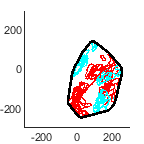

Error using matlab.ui.Figure/get
There is no TightInset property on the Figure class.

Error in figQuality (line 11)
    set(axh,'LooseInset',get(axh,'TightInset')) 

figQuality(gcf,gcf,[2.5 2.5])

% cKO mice
% cko8 = getACmaps(tmem1); %479_3
% cko2 = getACmaps(tmem2); %474_1
% cko4 = getACmaps(tmem4); %405_1
% cko5 = getACmaps(tmem5); %405_3
% cko6 = getACmaps(tmem6); %405_3
% cko7 = getACmaps(tmem7); %449_2
% cko8 = getACmaps(tmem8); %485_2
% cko9 = getACmaps(tmem9); %487_4
% cko10 = getACmaps(tmem10); %491_1
% cko11 = getACmaps(tmem11); %491_3
%cko12 = getACmaps(tmem12); %494_3
%save (['494_3_20dBmap.mat'],'cko12')


figure;
hold on
boundptsx = [];
boundptsy = [];
for x = 1:cko1(1).numbounds3 
    hold on
    plot(cko1(x).boundary3(:,2)-cko1(1).centroid(1,1),cko1(x).boundary3(:,1)-cko1(1).centroid(1,2),'c','LineWidth', 1)
    boundptsx = [boundptsx,(cko1(x).boundary3(:,2)-cko1(1).centroid(1,1))'];
    boundptsy = [boundptsy,(cko1(x).boundary3(:,1)-cko1(1).centroid(1,2))'];
end   
for x = 2:cko1(1).numbounds48 
    plot(cko1(x).boundary48(:,2)-cko1(1).centroid(1,1),cko1(x).boundary48(:,1)-cko1(1).centroid(1,2),'r','LineWidth', 1)
    boundptsx = [boundptsx,(cko1(x).boundary48(:,2)-cko1(1).centroid(1,1))'];
    boundptsy = [boundptsy,(cko1(x).boundary48(:,1)-cko1(1).centroid(1,2))'];
end
for x = 1:cko2(1).numbounds3 
    hold on
    boundptsx = [boundptsx,(cko2(x).boundary3(:,2)-cko2(1).centroid(1,1))'];
    boundptsy = [boundptsy,(cko2(x).boundary3(:,1)-cko2(1).centroid(1,2))'];
    plot(cko2(x).boundary3(:,2)-cko2(1).centroid(1,1),cko2(x).boundary3(:,1)-cko2(1).centroid(1,2),'c','LineWidth', 1)
end   
for x = 2:cko2(1).numbounds48 
    plot(cko2(x).boundary48(:,2)-cko2(1).centroid(1,1),cko2(x).boundary48(:,1)-cko2(1).centroid(1,2),'r','LineWidth', 1)
    boundptsx = [boundptsx,(cko2(x).boundary48(:,2)-cko2(1).centroid(1,1))'];
    boundptsy = [boundptsy,(cko2(x).boundary48(:,1)-cko2(1).centroid(1,2))'];
end
for x = 1:cko4(1).numbounds3 
    hold on
    plot(cko4(x).boundary3(:,2)-cko4(1).centroid(1,1),cko4(x).boundary3(:,1)-cko4(1).centroid(1,2),'c','LineWidth', 1)
        boundptsx = [boundptsx,(cko4(x).boundary3(:,2)-cko4(1).centroid(1,1))'];
    boundptsy = [boundptsy,(cko4(x).boundary3(:,1)-cko4(1).centroid(1,2))'];
end   
for x = 1:cko4(1).numbounds48 
    plot(cko4(x).boundary48(:,2)-cko4(1).centroid(1,1),cko4(x).boundary48(:,1)-cko4(1).centroid(1,2),'r','LineWidth', 1)
    boundptsx = [boundptsx,(cko4(x).boundary48(:,2)-cko4(1).centroid(1,1))'];
    boundptsy = [boundptsy,(cko4(x).boundary48(:,1)-cko4(1).centroid(1,2))'];
end
for x = 1:cko5(1).numbounds3 
    hold on
    plot(cko5(x).boundary3(:,2)-cko5(1).centroid(1,1),cko5(x).boundary3(:,1)-cko5(1).centroid(1,2),'c','LineWidth', 1)
        boundptsx = [boundptsx,(cko5(x).boundary3(:,2)-cko5(1).centroid(1,1))'];
    boundptsy = [boundptsy,(cko5(x).boundary3(:,1)-cko5(1).centroid(1,2))'];
end   
for x = 1:cko5(1).numbounds48 
    plot(cko5(x).boundary48(:,2)-cko5(1).centroid(1,1),cko5(x).boundary48(:,1)-cko5(1).centroid(1,2),'r','LineWidth', 1)
    boundptsx = [boundptsx,(cko5(x).boundary48(:,2)-cko5(1).centroid(1,1))'];
    boundptsy = [boundptsy,(cko5(x).boundary48(:,1)-cko5(1).centroid(1,2))'];
end
for x = 1:cko6(1).numbounds3 
    hold on
    plot(cko6(x).boundary3(:,2)-cko6(1).centroid(1,1),cko6(x).boundary3(:,1)-cko6(1).centroid(1,2),'c','LineWidth', 1)
    boundptsx = [boundptsx,(cko6(x).boundary3(:,2)-cko6(1).centroid(1,1))'];
    boundptsy = [boundptsy,(cko6(x).boundary3(:,1)-cko6(1).centroid(1,2))'];
end   
for x = 1:cko6(1).numbounds48 
    plot(cko6(x).boundary48(:,2)-cko6(1).centroid(1,1),cko6(x).boundary48(:,1)-cko6(1).centroid(1,2),'r','LineWidth', 1)
    boundptsx = [boundptsx,(cko6(x).boundary48(:,2)-cko6(1).centroid(1,1))'];
    boundptsy = [boundptsy,(cko6(x).boundary48(:,1)-cko6(1).centroid(1,2))'];
end
for x = 1:cko7(1).numbounds3 
    hold on
    plot(cko7(x).boundary3(:,2)-cko7(1).centroid(1,1),cko7(x).boundary3(:,1)-cko7(1).centroid(1,2),'c','LineWidth', 1)
    boundptsx = [boundptsx,(cko7(x).boundary3(:,2)-cko7(1).centroid(1,1))'];
    boundptsy = [boundptsy,(cko7(x).boundary3(:,1)-cko7(1).centroid(1,2))'];
end   
for x = 2:cko7(1).numbounds48 
    plot(cko7(x).boundary48(:,2)-cko7(1).centroid(1,1),cko7(x).boundary48(:,1)-cko7(1).centroid(1,2),'r','LineWidth', 1)
        boundptsx = [boundptsx,(cko7(x).boundary48(:,2)-cko7(1).centroid(1,1))'];
    boundptsy = [boundptsy,(cko7(x).boundary48(:,1)-cko7(1).centroid(1,2))'];
end
for x = 1:cko8(1).numbounds3 
    hold on
    plot(cko8(x).boundary3(:,2)-cko8(1).centroid(1,1),cko8(x).boundary3(:,1)-cko8(1).centroid(1,2),'c','LineWidth', 1)
    boundptsx = [boundptsx,(cko8(x).boundary3(:,2)-cko8(1).centroid(1,1))'];
    boundptsy = [boundptsy,(cko8(x).boundary3(:,1)-cko8(1).centroid(1,2))'];
end   
for x = 2:cko8(1).numbounds48 
    plot(cko8(x).boundary48(:,2)-cko8(1).centroid(1,1),cko8(x).boundary48(:,1)-cko8(1).centroid(1,2),'r','LineWidth', 1)
    boundptsx = [boundptsx,(cko8(x).boundary48(:,2)-cko8(1).centroid(1,1))'];
    boundptsy = [boundptsy,(cko8(x).boundary48(:,1)-cko8(1).centroid(1,2))'];
end
for x = 1:cko9(1).numbounds3 
    hold on
    plot(cko9(x).boundary3(:,2)-cko9(1).centroid(1,1),cko9(x).boundary3(:,1)-cko9(1).centroid(1,2),'c','LineWidth', 1)
    boundptsx = [boundptsx,(cko9(x).boundary3(:,2)-cko9(1).centroid(1,1))'];
    boundptsy = [boundptsy,(cko9(x).boundary3(:,1)-cko9(1).centroid(1,2))'];
end   
for x = 4:cko9(1).numbounds48 
    plot(cko9(x).boundary48(:,2)-cko9(1).centroid(1,1),cko9(x).boundary48(:,1)-cko9(1).centroid(1,2),'r','LineWidth', 1)
    boundptsx = [boundptsx,(cko9(x).boundary48(:,2)-cko9(1).centroid(1,1))'];
    boundptsy = [boundptsy,(cko9(x).boundary48(:,1)-cko9(1).centroid(1,2))'];
end
for x = 1:cko10(1).numbounds3 
    hold on
    plot(cko10(x).boundary3(:,2)-cko10(1).centroid(1,1),cko10(x).boundary3(:,1)-cko10(1).centroid(1,2),'c','LineWidth', 1)
        boundptsx = [boundptsx,(cko10(x).boundary3(:,2)-cko10(1).centroid(1,1))'];
    boundptsy = [boundptsy,(cko10(x).boundary3(:,1)-cko10(1).centroid(1,2))'];
end   
for x = 2:cko10(1).numbounds48 
    plot(cko10(x).boundary48(:,2)-cko10(1).centroid(1,1),cko10(x).boundary48(:,1)-cko10(1).centroid(1,2),'r','LineWidth', 1)
        boundptsx = [boundptsx,(cko10(x).boundary48(:,2)-cko10(1).centroid(1,1))'];
    boundptsy = [boundptsy,(cko10(x).boundary48(:,1)-cko10(1).centroid(1,2))'];
end
for x = 1:cko11(1).numbounds3 
    hold on
    plot(cko11(x).boundary3(:,2)-cko11(1).centroid(1,1),cko11(x).boundary3(:,1)-cko11(1).centroid(1,2),'c','LineWidth', 1)
            boundptsx = [boundptsx,(cko11(x).boundary3(:,2)-cko11(1).centroid(1,1))'];
    boundptsy = [boundptsy,(cko11(x).boundary3(:,1)-cko11(1).centroid(1,2))'];
end   
for x = 2:cko11(1).numbounds48 
    plot(cko11(x).boundary48(:,2)-cko11(1).centroid(1,1),cko11(x).boundary48(:,1)-cko11(1).centroid(1,2),'r','LineWidth', 1)
        boundptsx = [boundptsx,(cko11(x).boundary48(:,2)-cko11(1).centroid(1,1))'];
    boundptsy = [boundptsy,(cko11(x).boundary48(:,1)-cko11(1).centroid(1,2))'];
end
for x = 1:cko12(1).numbounds3 
    hold on
    plot(cko12(x).boundary3(:,2)-cko12(1).centroid(1,1),cko12(x).boundary3(:,1)-cko12(1).centroid(1,2),'c','LineWidth', 1)
    boundptsx = [boundptsx,(cko12(x).boundary3(:,2)-cko12(1).centroid(1,1))'];
    boundptsy = [boundptsy,(cko12(x).boundary3(:,1)-cko12(1).centroid(1,2))'];
end   
for x = 3:cko12(1).numbounds48 
    plot(cko12(x).boundary48(:,2)-cko12(1).centroid(1,1),cko12(x).boundary48(:,1)-cko12(1).centroid(1,2),'r','LineWidth', 1)
        boundptsx = [boundptsx,(cko12(x).boundary48(:,2)-cko12(1).centroid(1,1))'];
    boundptsy = [boundptsy,(cko12(x).boundary48(:,1)-cko12(1).centroid(1,2))'];
end
xlim([-300 300])
ylim([-300 300])


[k areacKO] = boundary(boundptsx',boundptsy',0)

k =          383
         386
         624
         625
         501
        4119
       10663
       10666
         853
         867


areacKO = 72406

plot(boundptsx(k),boundptsy(k),'k','LineWidth',2)
areacKOs = areacKO*(scale)*scale/1000/1000

areacKOs = 2.7686

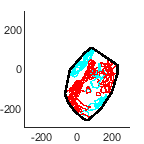

Error using matlab.ui.Figure/get
There is no TightInset property on the Figure class.

Error in figQuality (line 11)
    set(axh,'LooseInset',get(axh,'TightInset')) 

figQuality(gcf,gcf,[2.5 2.5])


% make averages of A1

% control A1 low
% figure
% hold on
% x = 1
% for x = 1:con11(1).numbounds3 
%     plot(con11(x).boundary3(:,2)-con11(1).centroid(1,1),con11(x).boundary3(:,1)-con11(1).centroid(1,2),'c','LineWidth', 1)
% end
% xlim([-300 300])
% ylim([-300 300])
con6A1L = 2;
con1A1L = 1;
con2A1L = 1;
con3A1L = 1;
con5A1L = 1;
con7A1L = 1;
con8A1L = 1;
con9A1L = 1;
con10A1L = 1;
con11A1L = 1;

% control A1 high
figure
hold on
x = 2

x = 2

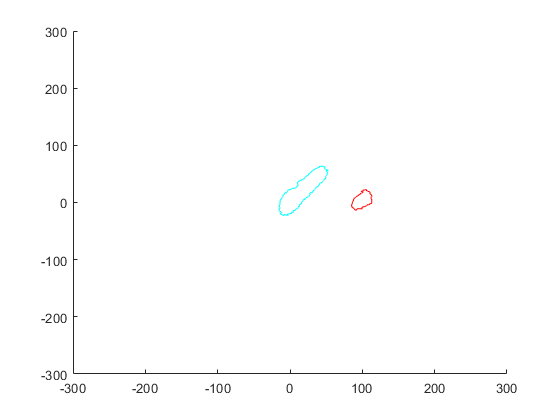

%for x = 1:con11(1).numbounds48 
    plot(con11(x).boundary48(:,2)-con11(1).centroid(1,1),con11(x).boundary48(:,1)-con11(1).centroid(1,2),'r','LineWidth', 1)
    plot(con11(1).boundary3(:,2)-con11(1).centroid(1,1),con11(1).boundary3(:,1)-con11(1).centroid(1,2),'c','LineWidth', 1)
%end
xlim([-300 300])
ylim([-300 300])


con1A1H = [4,5];
con2A1H = [2,3];
con3A1H = [2,3]; 
con5A1H = [2,4]; 
con6A1H = [4,6];
con7A1H = [3,4];
con8A1H = [2,3];
con9A1H = [2,3];
con10A1H = [3,4];
con11A1H = [1,2];



% generate mean of A1 low 
figure
A1lowcon = zeros(512,512);
bw = poly2mask([con1(1).boundary3(:,2)-con1(1).centroid(1,1)+200],[con1(1).boundary3(:,1)-con1(1).centroid(1,2)+300],512,512);
A1low1 = imfill(bw,'holes');
bw = poly2mask([con2(1).boundary3(:,2)-con2(1).centroid(1,1)+200],[con2(1).boundary3(:,1)-con2(1).centroid(1,2)+300],512,512);
A1low2 = imfill(bw,'holes');
bw = poly2mask([con3(1).boundary3(:,2)-con3(1).centroid(1,1)+200],[con3(1).boundary3(:,1)-con3(1).centroid(1,2)+300],512,512);
A1low3 = imfill(bw,'holes');
bw = poly2mask([con5(1).boundary3(:,2)-con5(1).centroid(1,1)+200],[con5(1).boundary3(:,1)-con5(1).centroid(1,2)+300],512,512);
A1low5 = imfill(bw,'holes');
bw = poly2mask([con6(2).boundary3(:,2)-con6(1).centroid(1,1)+200],[con6(2).boundary3(:,1)-con6(1).centroid(1,2)+300],512,512);
A1low6 = imfill(bw,'holes');
bw = poly2mask([con7(1).boundary3(:,2)-con7(1).centroid(1,1)+200],[con7(1).boundary3(:,1)-con7(1).centroid(1,2)+300],512,512);
A1low7 = imfill(bw,'holes');
bw = poly2mask([con8(1).boundary3(:,2)-con8(1).centroid(1,1)+200],[con8(1).boundary3(:,1)-con8(1).centroid(1,2)+300],512,512);
A1low8 = imfill(bw,'holes');
bw = poly2mask([con9(1).boundary3(:,2)-con9(1).centroid(1,1)+200],[con9(1).boundary3(:,1)-con9(1).centroid(1,2)+300],512,512);
A1low9 = imfill(bw,'holes');
bw = poly2mask([con11(1).boundary3(:,2)-con11(1).centroid(1,1)+200],[con11(1).boundary3(:,1)-con11(1).centroid(1,2)+300],512,512);
A1low11 = imfill(bw,'holes');
bw = poly2mask([con10(1).boundary3(:,2)-con10(1).centroid(1,1)+200],[con10(1).boundary3(:,1)-con10(1).centroid(1,2)+300],512,512);
A1low10 = imfill(bw,'holes');
A1lowcon = (A1low1+A1low2+A1low3+A1low5+A1low6+A1low7+A1low8+A1low9+A1low10+A1low11)./10

A1lowcon =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0  

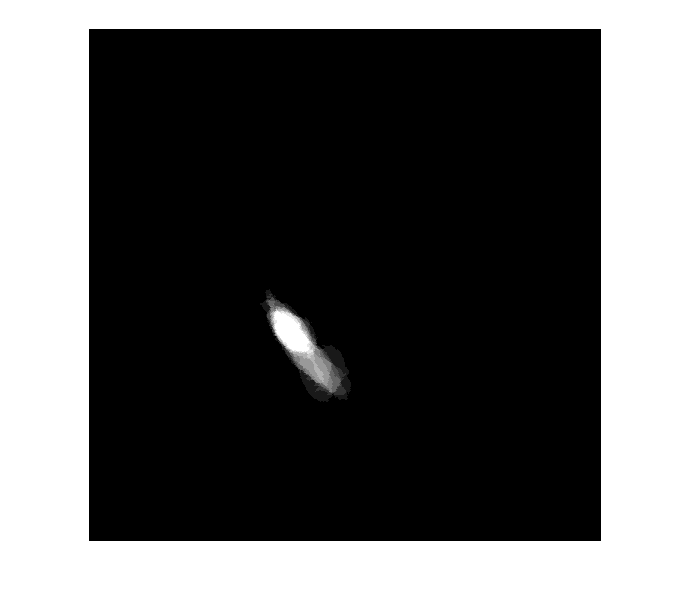

imshow(A1lowcon)

A1lowconavg = imbinarize(A1lowcon,0.3)

A1lowconavg = 512×512 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

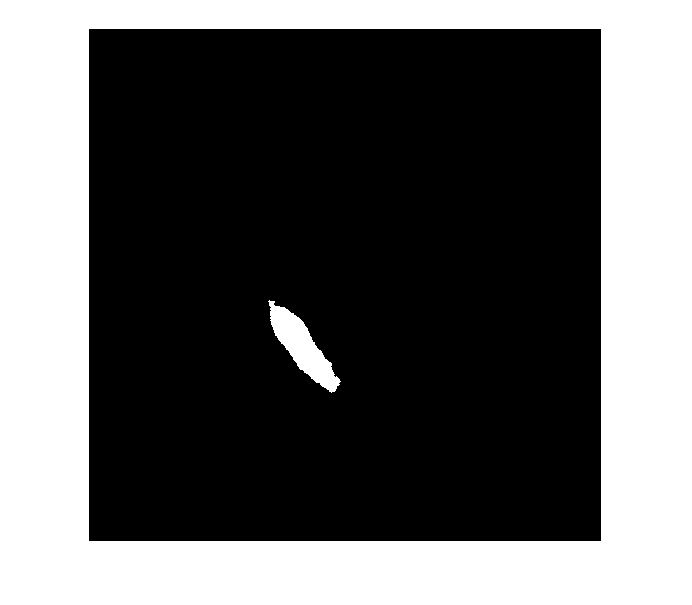

imshow(A1lowconavg)

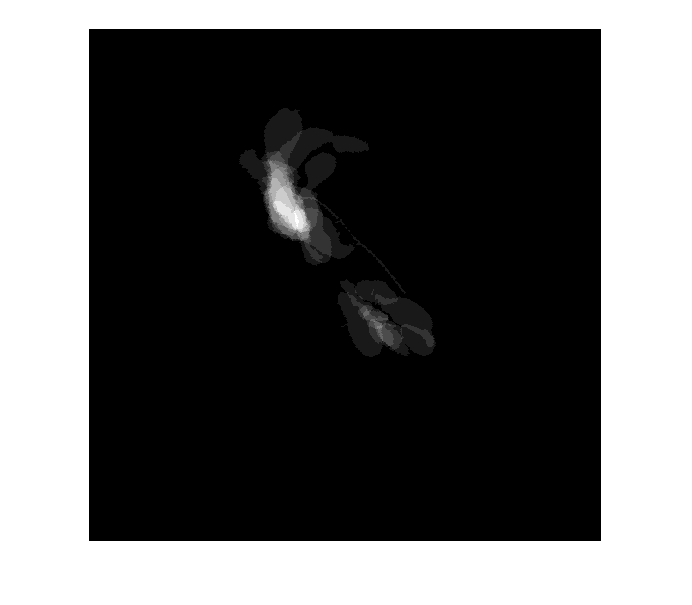

[B L] = bwboundaries(A1lowconavg, 'noholes');
Bconlow = B{1};

% generate mean of A1 high (2 locs)
figure
A1highcon = zeros(512,512);
bw = poly2mask([con1(4).boundary48(:,2)-con1(1).centroid(1,1)+200],[con1(4).boundary48(:,1)-con1(1).centroid(1,2)+300],512,512);
A1high1_1 = imfill(bw,'holes');
bw = poly2mask([con1(5).boundary48(:,2)-con1(1).centroid(1,1)+200],[con1(5).boundary48(:,1)-con1(1).centroid(1,2)+300],512,512);
A1high1_2 = imfill(bw,'holes');
bw = poly2mask([con2(2).boundary48(:,2)-con2(1).centroid(1,1)+200],[con2(2).boundary48(:,1)-con2(1).centroid(1,2)+300],512,512);
A1high2_1 = imfill(bw,'holes');
bw = poly2mask([con2(3).boundary48(:,2)-con2(1).centroid(1,1)+200],[con2(3).boundary48(:,1)-con2(1).centroid(1,2)+300],512,512);
A1high2_2 = imfill(bw,'holes');
bw = poly2mask([con3(2).boundary48(:,2)-con3(1).centroid(1,1)+200],[con3(2).boundary48(:,1)-con3(1).centroid(1,2)+300],512,512);
A1high3_1 = imfill(bw,'holes');
bw = poly2mask([con3(3).boundary48(:,2)-con3(1).centroid(1,1)+200],[con3(3).boundary48(:,1)-con3(1).centroid(1,2)+300],512,512);
A1high3_2 = imfill(bw,'holes');
bw = poly2mask([con5(2).boundary48(:,2)-con5(1).centroid(1,1)+200],[con5(2).boundary48(:,1)-con5(1).centroid(1,2)+300],512,512);
A1high5_1 = imfill(bw,'holes');
bw = poly2mask([con5(4).boundary48(:,2)-con5(1).centroid(1,1)+200],[con5(4).boundary48(:,1)-con5(1).centroid(1,2)+300],512,512);
A1high5_2 = imfill(bw,'holes');
bw = poly2mask([con6(4).boundary48(:,2)-con6(1).centroid(1,1)+200],[con6(4).boundary48(:,1)-con6(1).centroid(1,2)+300],512,512);
A1high6_1 = imfill(bw,'holes');
bw = poly2mask([con6(6).boundary48(:,2)-con6(1).centroid(1,1)+200],[con6(6).boundary48(:,1)-con6(1).centroid(1,2)+300],512,512);
A1high6_2 = imfill(bw,'holes');
bw = poly2mask([con7(3).boundary48(:,2)-con7(1).centroid(1,1)+200],[con7(3).boundary48(:,1)-con7(1).centroid(1,2)+300],512,512);
A1high7_1 = imfill(bw,'holes');
bw = poly2mask([con7(4).boundary48(:,2)-con7(1).centroid(1,1)+200],[con7(4).boundary48(:,1)-con7(1).centroid(1,2)+300],512,512);
A1high7_2 = imfill(bw,'holes');
bw = poly2mask([con8(2).boundary48(:,2)-con8(1).centroid(1,1)+200],[con8(2).boundary48(:,1)-con8(1).centroid(1,2)+300],512,512);
A1high8_1 = imfill(bw,'holes');
bw = poly2mask([con8(3).boundary48(:,2)-con8(1).centroid(1,1)+200],[con8(3).boundary48(:,1)-con8(1).centroid(1,2)+300],512,512);
A1high8_2 = imfill(bw,'holes');
bw = poly2mask([con9(2).boundary48(:,2)-con9(1).centroid(1,1)+200],[con9(2).boundary48(:,1)-con9(1).centroid(1,2)+300],512,512);
A1high9_1 = imfill(bw,'holes');
bw = poly2mask([con9(3).boundary48(:,2)-con9(1).centroid(1,1)+200],[con9(3).boundary48(:,1)-con9(1).centroid(1,2)+300],512,512);
A1high9_2 = imfill(bw,'holes');
bw = poly2mask([con10(4).boundary48(:,2)-con10(1).centroid(1,1)+200],[con10(4).boundary48(:,1)-con10(1).centroid(1,2)+300],512,512);
A1high10_1 = imfill(bw,'holes');
bw = poly2mask([con10(3).boundary48(:,2)-con10(1).centroid(1,1)+200],[con10(3).boundary48(:,1)-con10(1).centroid(1,2)+300],512,512);
A1high10_2 = imfill(bw,'holes');
bw = poly2mask([con11(1).boundary48(:,2)-con11(1).centroid(1,1)+200],[con11(1).boundary48(:,1)-con11(1).centroid(1,2)+300],512,512);
A1high11_1 = imfill(bw,'holes');
bw = poly2mask([con11(2).boundary48(:,2)-con11(1).centroid(1,1)+200],[con11(2).boundary48(:,1)-con11(1).centroid(1,2)+300],512,512);
A1high11_2 = imfill(bw,'holes');
A1highcon = (A1high1_1+A1high1_2+A1high2_1+A1high2_2+A1high3_1+A1high3_2+A1high5_1+A1high5_2+A1high6_1+A1high6_2+A1high7_1+A1high7_2+A1high8_1+A1high8_2+A1high9_1+A1high9_2+A1high10_1+A1high10_2+A1high11_1+A1high11_2)./10;
imshow(A1highcon)

A1highconavg = imbinarize(A1highcon,0.2)

A1highconavg = 512×512 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

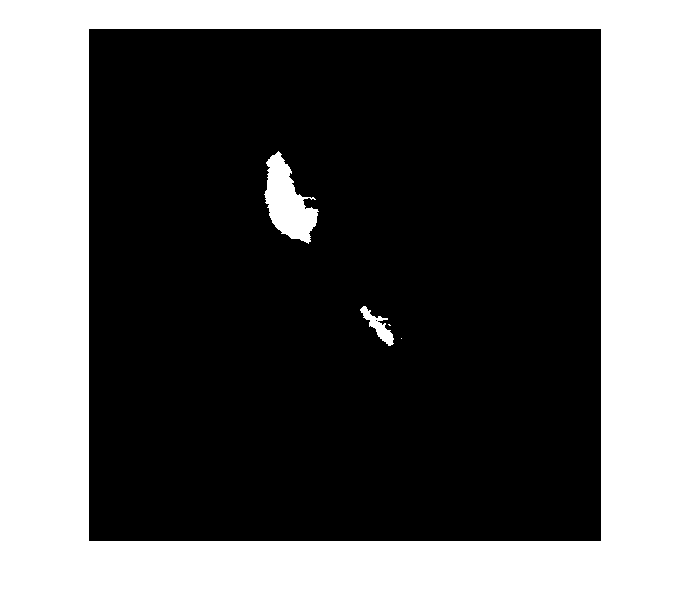

imshow(A1highconavg)

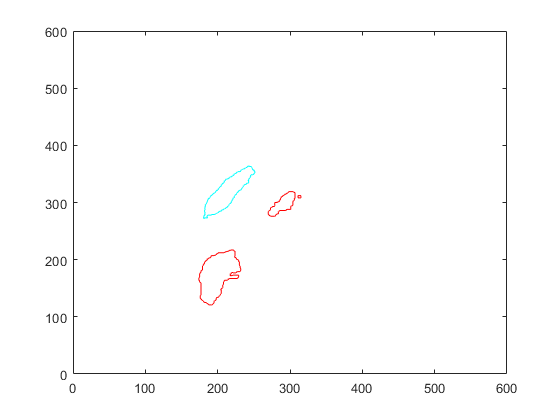

windowSize = 5;
kernel = ones(windowSize) / windowSize ^ 2;
blurryImage = conv2(single(A1highconavg), kernel, 'same');
[B1 L] = bwboundaries(blurryImage, 'noholes');
Bconhigh = struct;
for x = 1:size(B1,1)
    Bconhigh(x).bound = B1{x};    
end
figure;
plot([Bconlow(:,2)],Bconlow(:,1),'c')
hold on
for x = 1:size(B1,1)
   plot(Bconhigh(x).bound(:,2),Bconhigh(x).bound(:,1),'r') 
end
xlim([0 600])
ylim([0 600])

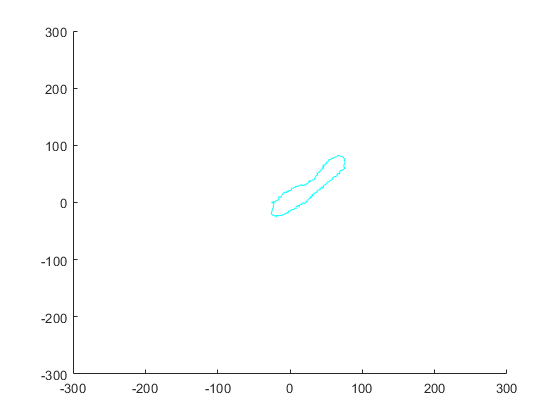


% cKO A1 low
figure
hold on
x = 1;
%for x = 1:cko9(1).numbounds3 
    plot(cko12(x).boundary3(:,2)-cko12(1).centroid(1,1),cko12(x).boundary3(:,1)-cko12(1).centroid(1,2),'c','LineWidth', 1)
%end   
xlim([-300 300])
ylim([-300 300])


cko1A1L = 1;
cko2A1L = 1;
cko4A1L = 1;
cko5A1L = 1;
cko6A1L = 1;
cko7A1L = 1;
cko8A1L = 1;
cko9A1L = 1;
cko10A1L = 1;
cko11A1L = 1;
cko12A1L = 1;

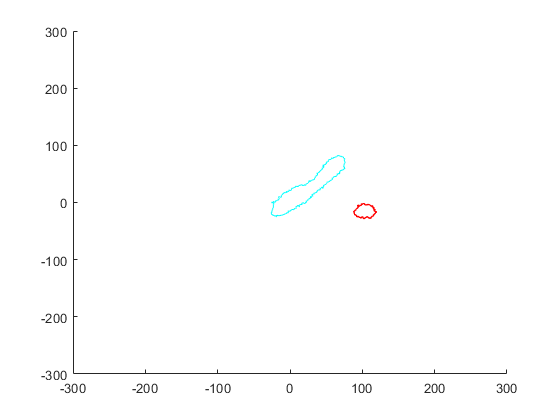


% cKO A1 high
figure
hold on
x = 6;
%for x = 1:cko12(1).numbounds48 
        plot(cko12(1).boundary3(:,2)-cko12(1).centroid(1,1),cko12(1).boundary3(:,1)-cko12(1).centroid(1,2),'c','LineWidth', 1)
    plot(cko12(x).boundary48(:,2)-cko12(1).centroid(1,1),cko12(x).boundary48(:,1)-cko12(1).centroid(1,2),'r','LineWidth', 1)
%end   
xlim([-300 300])
ylim([-300 300])


cko1A1H = [2,3];
cko2A1H = [3,4];
cko4A1H = [1,2];
cko5A1H = [1,2];
cko6A1H = [2,3];
cko7A1H = [2,4];
cko8A1H = [2,3];
cko9A1H = [4,6];
cko10A1H = [2,3];
cko11A1H = [3,4];
cko12A1H = [4,6];


% generate mean of A1 low 
figure
A1lowcko = zeros(512,512);
bw = poly2mask([cko1(1).boundary3(:,2)-cko1(1).centroid(1,1)+200],[cko1(1).boundary3(:,1)-cko1(1).centroid(1,2)+300],512,512);
A1low1 = imfill(bw,'holes');
bw = poly2mask([cko2(1).boundary3(:,2)-cko2(1).centroid(1,1)+200],[cko2(1).boundary3(:,1)-cko2(1).centroid(1,2)+300],512,512);
A1low2 = imfill(bw,'holes');
bw = poly2mask([cko4(1).boundary3(:,2)-cko4(1).centroid(1,1)+200],[cko4(1).boundary3(:,1)-cko4(1).centroid(1,2)+300],512,512);
A1low4 = imfill(bw,'holes');
bw = poly2mask([cko5(1).boundary3(:,2)-cko5(1).centroid(1,1)+200],[cko5(1).boundary3(:,1)-cko5(1).centroid(1,2)+300],512,512);
A1low5 = imfill(bw,'holes');
bw = poly2mask([cko6(1).boundary3(:,2)-cko6(1).centroid(1,1)+200],[cko6(1).boundary3(:,1)-cko6(1).centroid(1,2)+300],512,512);
A1low6 = imfill(bw,'holes');
bw = poly2mask([cko7(1).boundary3(:,2)-cko7(1).centroid(1,1)+200],[cko7(1).boundary3(:,1)-cko7(1).centroid(1,2)+300],512,512);
A1low7 = imfill(bw,'holes');
bw = poly2mask([cko8(1).boundary3(:,2)-cko8(1).centroid(1,1)+200],[cko8(1).boundary3(:,1)-cko8(1).centroid(1,2)+300],512,512);
A1low8 = imfill(bw,'holes');
bw = poly2mask([cko9(1).boundary3(:,2)-cko9(1).centroid(1,1)+200],[cko9(1).boundary3(:,1)-cko9(1).centroid(1,2)+300],512,512);
A1low9 = imfill(bw,'holes');
bw = poly2mask([cko11(1).boundary3(:,2)-cko11(1).centroid(1,1)+200],[cko11(1).boundary3(:,1)-cko11(1).centroid(1,2)+300],512,512);
A1low11 = imfill(bw,'holes');
bw = poly2mask([cko12(1).boundary3(:,2)-cko12(1).centroid(1,1)+200],[cko12(1).boundary3(:,1)-cko12(1).centroid(1,2)+300],512,512);
A1low12 = imfill(bw,'holes');
bw = poly2mask([cko10(1).boundary3(:,2)-cko10(1).centroid(1,1)+200],[cko10(1).boundary3(:,1)-cko10(1).centroid(1,2)+300],512,512);
A1low10 = imfill(bw,'holes');
A1lowcko = (A1low1+A1low2+A1low4+A1low5+A1low6+A1low7+A1low8+A1low9+A1low10+A1low11+A1low12)./11

A1lowcko =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0  

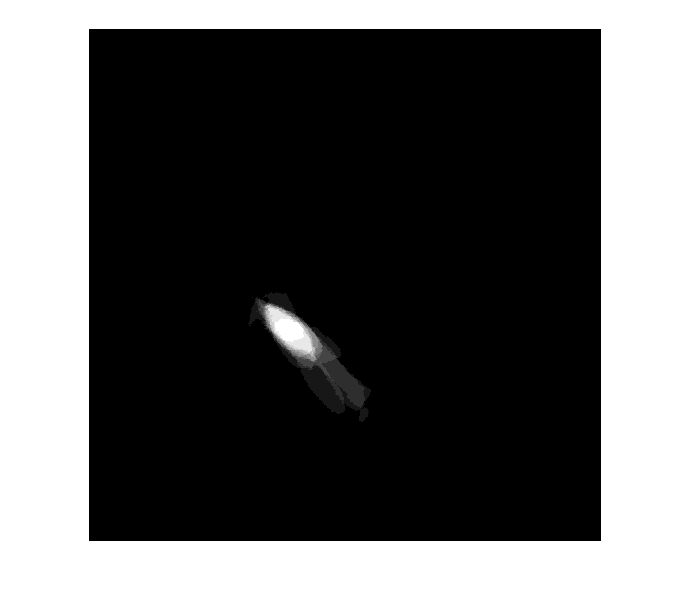

imshow(A1lowcko)

A1lowckoavg = imbinarize(A1lowcko,0.3)

A1lowckoavg = 512×512 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

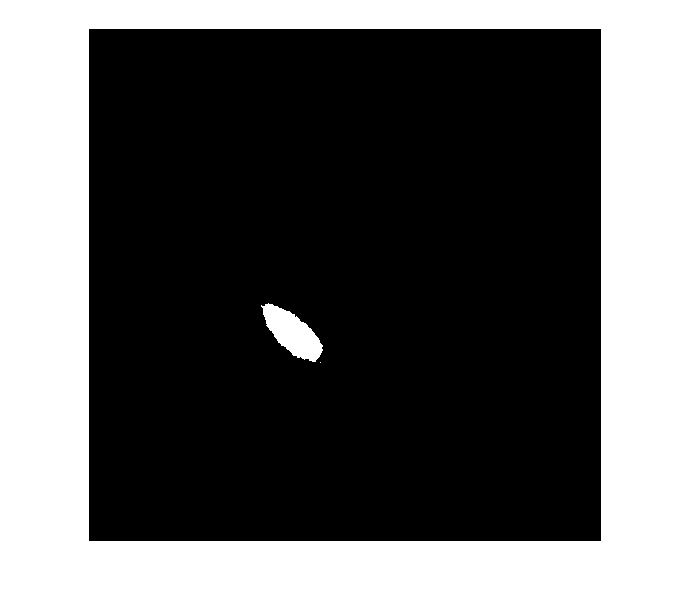

imshow(A1lowckoavg)

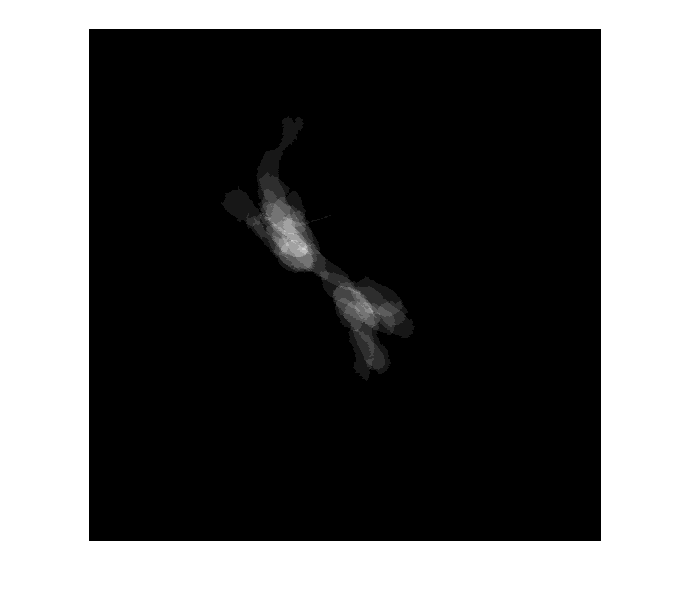

[B L] = bwboundaries(A1lowckoavg, 'noholes');
Bckolow = B{1};

% generate mean of A1 high (2 locs)
figure
A1highcko = zeros(512,512);
bw = poly2mask([cko1(2).boundary48(:,2)-cko1(1).centroid(1,1)+200],[cko1(2).boundary48(:,1)-cko1(1).centroid(1,2)+300],512,512);
A1high1_1 = imfill(bw,'holes');
bw = poly2mask([cko1(3).boundary48(:,2)-cko1(1).centroid(1,1)+200],[cko1(3).boundary48(:,1)-cko1(1).centroid(1,2)+300],512,512);
A1high1_2 = imfill(bw,'holes');
bw = poly2mask([cko2(3).boundary48(:,2)-cko2(1).centroid(1,1)+200],[cko2(3).boundary48(:,1)-cko2(1).centroid(1,2)+300],512,512);
A1high2_1 = imfill(bw,'holes');
bw = poly2mask([cko2(4).boundary48(:,2)-cko2(1).centroid(1,1)+200],[cko2(4).boundary48(:,1)-cko2(1).centroid(1,2)+300],512,512);
A1high2_2 = imfill(bw,'holes');
bw = poly2mask([cko4(1).boundary48(:,2)-cko4(1).centroid(1,1)+200],[cko4(1).boundary48(:,1)-cko4(1).centroid(1,2)+300],512,512);
A1high4_1 = imfill(bw,'holes');
bw = poly2mask([cko4(2).boundary48(:,2)-cko4(1).centroid(1,1)+200],[cko4(2).boundary48(:,1)-cko4(1).centroid(1,2)+300],512,512);
A1high4_2 = imfill(bw,'holes');
bw = poly2mask([cko5(1).boundary48(:,2)-cko5(1).centroid(1,1)+200],[cko5(1).boundary48(:,1)-cko5(1).centroid(1,2)+300],512,512);
A1high5_1 = imfill(bw,'holes');
bw = poly2mask([cko5(2).boundary48(:,2)-cko5(1).centroid(1,1)+200],[cko5(2).boundary48(:,1)-cko5(1).centroid(1,2)+300],512,512);
A1high5_2 = imfill(bw,'holes');
bw = poly2mask([cko6(2).boundary48(:,2)-cko6(1).centroid(1,1)+200],[cko6(2).boundary48(:,1)-cko6(1).centroid(1,2)+300],512,512);
A1high6_1 = imfill(bw,'holes');
bw = poly2mask([cko6(3).boundary48(:,2)-cko6(1).centroid(1,1)+200],[cko6(3).boundary48(:,1)-cko6(1).centroid(1,2)+300],512,512);
A1high6_2 = imfill(bw,'holes');
bw = poly2mask([cko7(2).boundary48(:,2)-cko7(1).centroid(1,1)+200],[cko7(2).boundary48(:,1)-cko7(1).centroid(1,2)+300],512,512);
A1high7_1 = imfill(bw,'holes');
bw = poly2mask([cko7(4).boundary48(:,2)-cko7(1).centroid(1,1)+200],[cko7(4).boundary48(:,1)-cko7(1).centroid(1,2)+300],512,512);
A1high7_2 = imfill(bw,'holes');
bw = poly2mask([cko8(2).boundary48(:,2)-cko8(1).centroid(1,1)+200],[cko8(2).boundary48(:,1)-cko8(1).centroid(1,2)+300],512,512);
A1high8_1 = imfill(bw,'holes');
bw = poly2mask([cko8(3).boundary48(:,2)-cko8(1).centroid(1,1)+200],[cko8(3).boundary48(:,1)-cko8(1).centroid(1,2)+300],512,512);
A1high8_2 = imfill(bw,'holes');
bw = poly2mask([cko9(4).boundary48(:,2)-cko9(1).centroid(1,1)+200],[cko9(4).boundary48(:,1)-cko9(1).centroid(1,2)+300],512,512);
A1high9_1 = imfill(bw,'holes');
bw = poly2mask([cko9(6).boundary48(:,2)-cko9(1).centroid(1,1)+200],[cko9(6).boundary48(:,1)-cko9(1).centroid(1,2)+300],512,512);
A1high9_2 = imfill(bw,'holes');
bw = poly2mask([cko10(2).boundary48(:,2)-cko10(1).centroid(1,1)+200],[cko10(2).boundary48(:,1)-cko10(1).centroid(1,2)+300],512,512);
A1high10_1 = imfill(bw,'holes');
bw = poly2mask([cko10(3).boundary48(:,2)-cko10(1).centroid(1,1)+200],[cko10(3).boundary48(:,1)-cko10(1).centroid(1,2)+300],512,512);
A1high10_2 = imfill(bw,'holes');
bw = poly2mask([cko11(3).boundary48(:,2)-cko11(1).centroid(1,1)+200],[cko11(3).boundary48(:,1)-cko11(1).centroid(1,2)+300],512,512);
A1high11_1 = imfill(bw,'holes');
bw = poly2mask([cko11(4).boundary48(:,2)-cko11(1).centroid(1,1)+200],[cko11(4).boundary48(:,1)-cko11(1).centroid(1,2)+300],512,512);
A1high11_2 = imfill(bw,'holes');
bw = poly2mask([cko12(4).boundary48(:,2)-cko12(1).centroid(1,1)+200],[cko12(4).boundary48(:,1)-cko12(1).centroid(1,2)+300],512,512);
A1high12_1 = imfill(bw,'holes');
bw = poly2mask([cko12(6).boundary48(:,2)-cko12(1).centroid(1,1)+200],[cko12(6).boundary48(:,1)-cko12(1).centroid(1,2)+300],512,512);
A1high12_2 = imfill(bw,'holes');
A1highcko = (A1high1_1+A1high1_2+A1high2_1+A1high2_2+A1high4_1+A1high4_2+A1high5_1+A1high5_2+A1high6_1+A1high6_2+A1high7_1+A1high7_2+A1high8_1+A1high8_2+A1high9_1+A1high9_2+A1high10_1+A1high10_2+A1high11_1+A1high11_2+A1high12_1+A1high12_2)./11;
imshow(A1highcko)

A1highckoavg = imbinarize(A1highcko,0.2)

A1highckoavg = 512×512 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

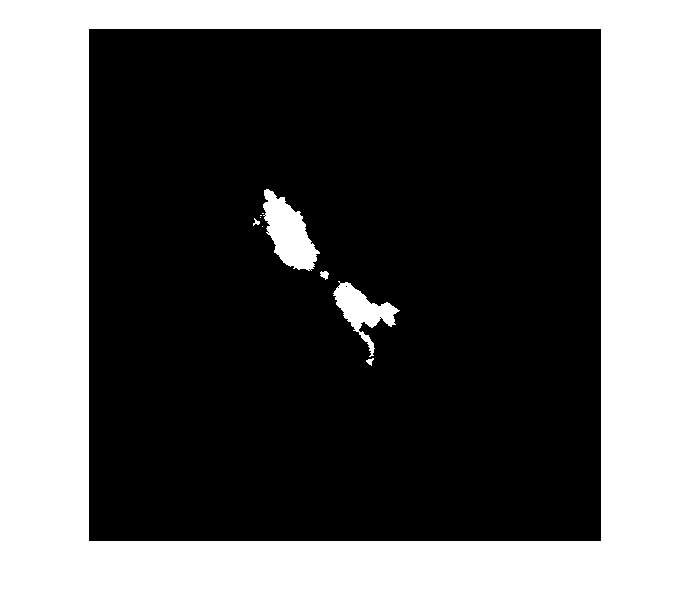

imshow(A1highckoavg); 

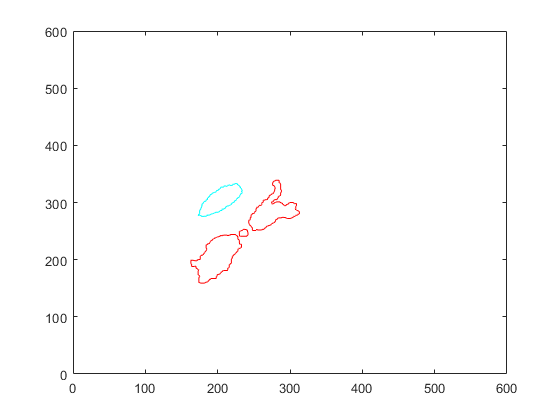

windowSize = 5;
kernel = ones(windowSize) / windowSize ^ 2;
blurryImage = conv2(single(A1highckoavg), kernel, 'same');
[B L] = bwboundaries(blurryImage, 'noholes');
Bckohigh = struct;
for x = 1:size(B,1)
    Bckohigh(x).bound = B{x};    
end
figure;
plot([Bckolow(:,2)],Bckolow(:,1),'c')
hold on
for x = 1:size(B,1)
   plot(Bckohigh(x).bound(:,2),Bckohigh(x).bound(:,1),'r') 
end
xlim([0 600])
ylim([0 600])

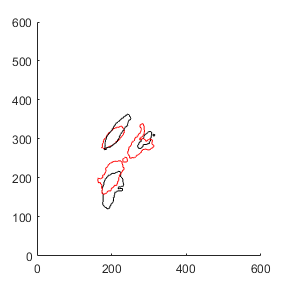

Error using matlab.ui.Figure/get
There is no TightInset property on the Figure class.

Error in figQuality (line 11)
    set(axh,'LooseInset',get(axh,'TightInset')) 


% combine con and cKO

figure;
plot([Bckolow(:,2)],Bckolow(:,1),'r')
hold on
plot([Bconlow(:,2)],Bconlow(:,1),'k')
for x = 1:size(B1,1)
   plot(Bconhigh(x).bound(:,2),Bconhigh(x).bound(:,1),'k') 
end

for x = 1:size(B,1)
   plot(Bckohigh(x).bound(:,2),Bckohigh(x).bound(:,1),'r') 
end
xlim([0 600])
ylim([0 600])
figQuality(gcf,gcf,[3 3])


% mean with bounds - combined
figure;
boundptsxcko = [];
boundptsycko = [];
boundptsxcon = [];
boundptsycon = [];
plot([smooth(Bckolow(:,2))],smooth(Bckolow(:,1)),'r')
boundptsxcko = [boundptsxcko,([Bckolow(:,2)])'];
boundptsycko = [boundptsycko,(Bckolow(:,1))'];
hold on
plot([smooth(Bconlow(:,2))],smooth(Bconlow(:,1)),'k')
boundptsxcon = [boundptsxcon,([Bconlow(:,2)])'];
boundptsycon = [boundptsycon,(Bconlow(:,1))'];
for x = 1:size(B1,1)
   plot(smooth(Bconhigh(x).bound(:,2)),smooth(Bconhigh(x).bound(:,1)),'k')
   boundptsxcon = [boundptsxcon,(Bconhigh(x).bound(:,2))'];
boundptsycon = [boundptsycon,(Bconhigh(x).bound(:,1))'];
end

for x = 1:size(B,1)
   plot(smooth(Bckohigh(x).bound(:,2)),smooth(Bckohigh(x).bound(:,1)),'r') 
   boundptsxcko = [boundptsxcko,(Bckohigh(x).bound(:,2))'];
    boundptsycko = [boundptsycko,(Bckohigh(x).bound(:,1))'];
end
xlim([0 600])
ylim([0 600]) 
[k areacKO] = boundary(boundptsxcko',boundptsycko',0)

k =     89
    98
   105
   110
   124
   128
   134
   143
   148
   157


areacKO = 16371

[k2 areacon] = boundary(boundptsxcon',boundptsycon',0)

k2 =    114
   115
   116
   132
   153
   157
   190
   201
   205
   221


areacon = 18379

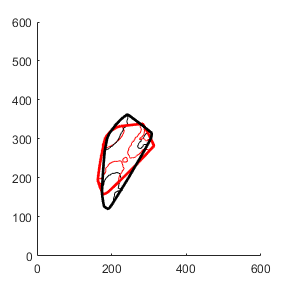

Error using matlab.ui.Figure/get
There is no TightInset property on the Figure class.

Error in figQuality (line 11)
    set(axh,'LooseInset',get(axh,'TightInset')) 


plot(smooth(boundptsxcko(k)),smooth(boundptsycko(k)),'r','LineWidth',2)
plot(smooth(boundptsxcon(k2)),smooth(boundptsycon(k2)),'k','LineWidth',2)
figQuality(gcf,gcf,[3 3])


% get A1 area (by animal)
scale = 6.1836; % microns per pixel
%cko1
figure;
hold on
boundptsx = [];
boundptsy = [];
x = 1;
y1 = 2;
y2 = 3;
    hold on
    plot(cko1(x).boundary3(:,2)-cko1(1).centroid(1,1),cko1(x).boundary3(:,1)-cko1(1).centroid(1,2),'c','LineWidth', 1)
    [cenLowcko1x cenLowcko1y] = centroid(polyshape([cko1(x).boundary3(:,2)-cko1(1).centroid(1,1)],[cko1(x).boundary3(:,1)-cko1(1).centroid(1,2)]));

    plot(cenLowcko1x,cenLowcko1y,'c*')
    boundptsx = [boundptsx,(cko1(1).boundary3(:,2)-cko1(1).centroid(1,1))'];
    boundptsy = [boundptsy,(cko1(1).boundary3(:,1)-cko1(1).centroid(1,2))'];
    plot(cko1(y1).boundary48(:,2)-cko1(1).centroid(1,1),cko1(y1).boundary48(:,1)-cko1(1).centroid(1,2),'r','LineWidth', 1)
    [cenHi1cko1x cenHi1cko1y] = centroid(polyshape([cko1(y1).boundary48(:,2)-cko1(1).centroid(1,1)],[cko1(y1).boundary48(:,1)-cko1(1).centroid(1,2)]));

    plot(cenHi1cko1x,cenHi1cko1y,'r*')
    boundptsx = [boundptsx,(cko1(y1).boundary48(:,2)-cko1(1).centroid(1,1))'];
    boundptsy = [boundptsy,(cko1(y1).boundary48(:,1)-cko1(1).centroid(1,2))'];
    plot(cko1(y2).boundary48(:,2)-cko1(1).centroid(1,1),cko1(y2).boundary48(:,1)-cko1(1).centroid(1,2),'r','LineWidth', 1)
    [cenHi2cko1x cenHi2cko1y] = centroid(polyshape([cko1(y2).boundary48(:,2)-cko1(1).centroid(1,1)],[cko1(y2).boundary48(:,1)-cko1(1).centroid(1,2)]));

    plot(cenHi2cko1x,cenHi2cko1y,'g*')
    boundptsx = [boundptsx,(cko1(y2).boundary48(:,2)-cko1(1).centroid(1,1))'];
    boundptsy = [boundptsy,(cko1(y2).boundary48(:,1)-cko1(1).centroid(1,2))'];
    [k areacKO] = boundary(boundptsx',boundptsy',0)

k =    178
   179
   180
   211
   215
   219
   220
   221
   223
   383


areacKO = 18043

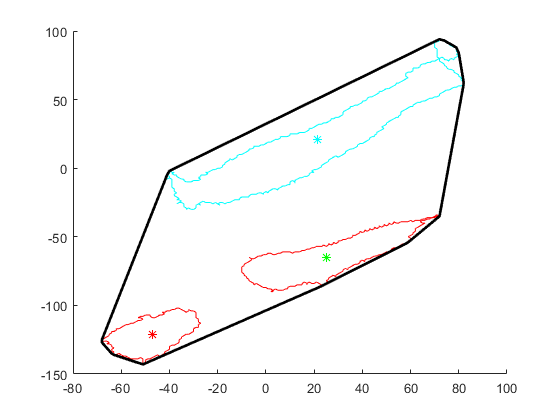

plot(boundptsx(k),boundptsy(k),'k','LineWidth',2)

areacKO1 = areacKO*(scale)*scale/1000/1000

areacKO1 = 0.6899

cko1LHi1 = NaN;
cko1LHi2 = sqrt((cenHi2cko1x-cenLowcko1x)^2+(cenHi2cko1y-cenLowcko1y)^2)*scale;
cko1Hi1Hi2 = sqrt((cenHi2cko1x-cenHi1cko1x)^2+(cenHi2cko1y-cenHi1cko1y)^2)*scale;

figure;
hold on
boundptsx = [];
boundptsy = [];
x = 1;
y1 = 3;
y2 = 4;
    hold on
    plot(cko2(x).boundary3(:,2)-cko2(1).centroid(1,1),cko2(x).boundary3(:,1)-cko2(1).centroid(1,2),'c','LineWidth', 1)
    [cenLowcko2x cenLowcko2y] = centroid(polyshape([cko2(x).boundary3(:,2)-cko2(1).centroid(1,1)],[cko2(x).boundary3(:,1)-cko2(1).centroid(1,2)]));

    plot(cenLowcko2x,cenLowcko2y,'c*')
    boundptsx = [boundptsx,(cko2(1).boundary3(:,2)-cko2(1).centroid(1,1))'];
    boundptsy = [boundptsy,(cko2(1).boundary3(:,1)-cko2(1).centroid(1,2))'];
    plot(cko2(y1).boundary48(:,2)-cko2(1).centroid(1,1),cko2(y1).boundary48(:,1)-cko2(1).centroid(1,2),'r','LineWidth', 1)
    [cenHi1cko2x cenHi1cko2y] = centroid(polyshape([cko2(y1).boundary48(:,2)-cko2(1).centroid(1,1)],[cko2(y1).boundary48(:,1)-cko2(1).centroid(1,2)]));

    plot(cenHi1cko2x,cenHi1cko2y,'r*')
    boundptsx = [boundptsx,(cko2(y1).boundary48(:,2)-cko2(1).centroid(1,1))'];
    boundptsy = [boundptsy,(cko2(y1).boundary48(:,1)-cko2(1).centroid(1,2))'];
    plot(cko2(y2).boundary48(:,2)-cko2(1).centroid(1,1),cko2(y2).boundary48(:,1)-cko2(1).centroid(1,2),'r','LineWidth', 1)
    [cenHi2cko2x cenHi2cko2y] = centroid(polyshape([cko2(y2).boundary48(:,2)-cko2(1).centroid(1,1)],[cko2(y2).boundary48(:,1)-cko2(1).centroid(1,2)]));

    plot(cenHi2cko2x,cenHi2cko2y,'g*')
    boundptsx = [boundptsx,(cko2(y2).boundary48(:,2)-cko2(1).centroid(1,1))'];
    boundptsy = [boundptsy,(cko2(y2).boundary48(:,1)-cko2(1).centroid(1,2))'];
    [k areacKO] = boundary(boundptsx',boundptsy',0)

k =      1
   171
   176
   180
   184
   185
   186
   187
   188
   193


areacKO = 1.3648e+04

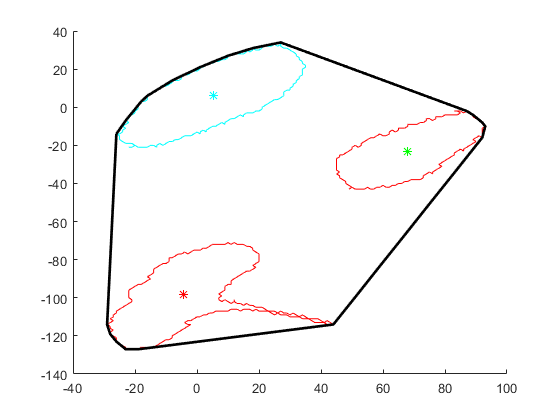

plot(boundptsx(k),boundptsy(k),'k','LineWidth',2)

areacKO2 = areacKO*(scale)*scale/1000/1000

areacKO2 = 0.5218

cko2LHi1 = sqrt((cenHi1cko2x-cenLowcko2x)^2+(cenHi1cko2y-cenLowcko2y)^2)*scale;
cko2LHi2 = sqrt((cenHi2cko2x-cenLowcko2x)^2+(cenHi2cko2y-cenLowcko2y)^2)*scale;
cko2Hi1Hi2 = sqrt((cenHi2cko2x-cenHi1cko2x)^2+(cenHi2cko2y-cenHi1cko2y)^2)*scale;

figure;
hold on
boundptsx = [];
boundptsy = [];
x = 1;
y1 = 1;
y2 = 2;
    hold on
    plot(cko4(x).boundary3(:,2)-cko4(1).centroid(1,1),cko4(x).boundary3(:,1)-cko4(1).centroid(1,2),'c','LineWidth', 1)
        [cenLowcko4x cenLowcko4y] = centroid(polyshape([cko4(x).boundary3(:,2)-cko4(1).centroid(1,1)],[cko4(x).boundary3(:,1)-cko4(1).centroid(1,2)]));

    plot(cenLowcko4x,cenLowcko4y,'c*')
    boundptsx = [boundptsx,(cko4(1).boundary3(:,2)-cko4(1).centroid(1,1))'];
    boundptsy = [boundptsy,(cko4(1).boundary3(:,1)-cko4(1).centroid(1,2))'];
    plot(cko4(y1).boundary48(:,2)-cko4(1).centroid(1,1),cko4(y1).boundary48(:,1)-cko4(1).centroid(1,2),'r','LineWidth', 1)
        [cenHi1cko4x cenHi1cko4y] = centroid(polyshape([cko4(y1).boundary48(:,2)-cko4(1).centroid(1,1)],[cko4(y1).boundary48(:,1)-cko4(1).centroid(1,2)]));

    plot(cenHi1cko4x,cenHi1cko4y,'r*')
    boundptsx = [boundptsx,(cko4(y1).boundary48(:,2)-cko4(1).centroid(1,1))'];
    boundptsy = [boundptsy,(cko4(y1).boundary48(:,1)-cko4(1).centroid(1,2))'];
    plot(cko4(y2).boundary48(:,2)-cko4(1).centroid(1,1),cko4(y2).boundary48(:,1)-cko4(1).centroid(1,2),'r','LineWidth', 1)
        [cenHi2cko4x cenHi2cko4y] = centroid(polyshape([cko4(y2).boundary48(:,2)-cko4(1).centroid(1,1)],[cko4(y2).boundary48(:,1)-cko4(1).centroid(1,2)]));

    plot(cenHi2cko4x,cenHi2cko4y,'g*')
    boundptsx = [boundptsx,(cko4(y2).boundary48(:,2)-cko4(1).centroid(1,1))'];
    boundptsy = [boundptsy,(cko4(y2).boundary48(:,1)-cko4(1).centroid(1,2))'];
    [k areacKO] = boundary(boundptsx',boundptsy',0)

k =     99
   107
   127
   131
   142
   159
   160
   164
   188
   392


areacKO = 9.9685e+03

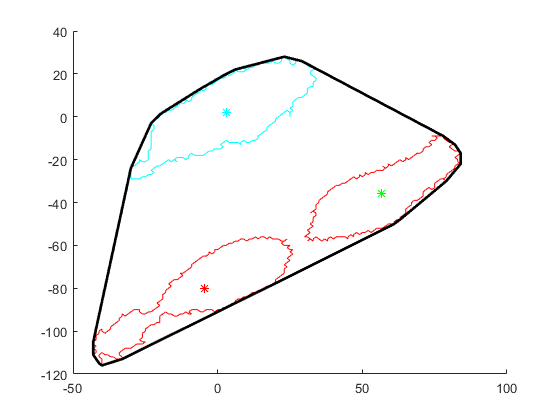

plot(boundptsx(k),boundptsy(k),'k','LineWidth',2)

areacKO4 = areacKO*(scale)*scale/1000/1000

areacKO4 = 0.3812

cko4LHi1 = sqrt((cenHi1cko4x-cenLowcko4x)^2+(cenHi1cko4y-cenLowcko4y)^2)*scale;
cko4LHi2 = sqrt((cenHi2cko4x-cenLowcko4x)^2+(cenHi2cko4y-cenLowcko4y)^2)*scale;
cko4Hi1Hi2 = sqrt((cenHi2cko4x-cenHi1cko4x)^2+(cenHi2cko4y-cenHi1cko4y)^2)*scale;

figure;
hold on
boundptsx = [];
boundptsy = [];
x = 1;
y1 = 1;
y2 = 2;
    hold on
    plot(cko5(x).boundary3(:,2)-cko5(1).centroid(1,1),cko5(x).boundary3(:,1)-cko5(1).centroid(1,2),'c','LineWidth', 1)
            [cenLowcko5x cenLowcko5y] = centroid(polyshape([cko5(x).boundary3(:,2)-cko5(1).centroid(1,1)],[cko5(x).boundary3(:,1)-cko5(1).centroid(1,2)]));

    plot(cenLowcko5x,cenLowcko5y,'c*')
    boundptsx = [boundptsx,(cko5(1).boundary3(:,2)-cko5(1).centroid(1,1))'];
    boundptsy = [boundptsy,(cko5(1).boundary3(:,1)-cko5(1).centroid(1,2))'];
    plot(cko5(y1).boundary48(:,2)-cko5(1).centroid(1,1),cko5(y1).boundary48(:,1)-cko5(1).centroid(1,2),'r','LineWidth', 1)
            [cenHi1cko5x cenHi1cko5y] = centroid(polyshape([cko5(y1).boundary48(:,2)-cko5(1).centroid(1,1)],[cko5(y1).boundary48(:,1)-cko5(1).centroid(1,2)]));

    plot(cenHi1cko5x,cenHi1cko5y,'r*')
    boundptsx = [boundptsx,(cko5(y1).boundary48(:,2)-cko5(1).centroid(1,1))'];
    boundptsy = [boundptsy,(cko5(y1).boundary48(:,1)-cko5(1).centroid(1,2))'];
    plot(cko5(y2).boundary48(:,2)-cko5(1).centroid(1,1),cko5(y2).boundary48(:,1)-cko5(1).centroid(1,2),'r','LineWidth', 1)
            [cenHi2cko5x cenHi2cko5y] = centroid(polyshape([cko5(y2).boundary48(:,2)-cko5(1).centroid(1,1)],[cko5(y2).boundary48(:,1)-cko5(1).centroid(1,2)]));

    plot(cenHi2cko5x,cenHi2cko5y,'g*')
    boundptsx = [boundptsx,(cko5(y2).boundary48(:,2)-cko5(1).centroid(1,1))'];
    boundptsy = [boundptsy,(cko5(y2).boundary48(:,1)-cko5(1).centroid(1,2))'];
    [k areacKO] = boundary(boundptsx',boundptsy',0)

k =     64
    65
    66
    67
    69
    72
    75
    77
    80
    81


areacKO = 7608

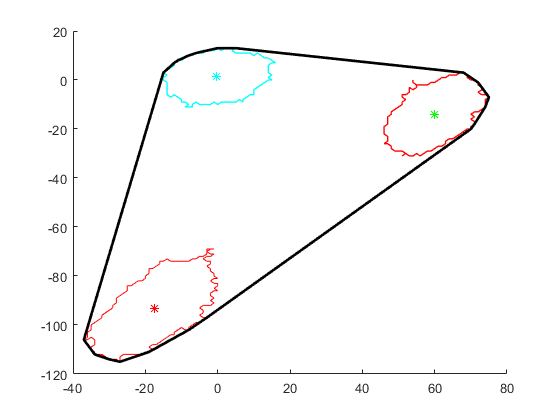

plot(boundptsx(k),boundptsy(k),'k','LineWidth',2)

areacKO5 = areacKO*(scale)*scale/1000/1000

areacKO5 = 0.2909

cko5LHi1 = sqrt((cenHi1cko5x-cenLowcko5x)^2+(cenHi1cko5y-cenLowcko5y)^2)*scale;
cko5LHi2 = sqrt((cenHi2cko5x-cenLowcko5x)^2+(cenHi2cko5y-cenLowcko5y)^2)*scale;
cko5Hi1Hi2 = sqrt((cenHi2cko5x-cenHi1cko5x)^2+(cenHi2cko5y-cenHi1cko5y)^2)*scale;

figure;
hold on
boundptsx = [];
boundptsy = [];
x = 1;
y1 = 2;
y2 = 3;
    hold on
    plot(cko6(x).boundary3(:,2)-cko6(1).centroid(1,1),cko6(x).boundary3(:,1)-cko6(1).centroid(1,2),'c','LineWidth', 1)
                [cenLowcko6x cenLowcko6y] = centroid(polyshape([cko6(x).boundary3(:,2)-cko6(1).centroid(1,1)],[cko6(x).boundary3(:,1)-cko6(1).centroid(1,2)]));

    plot(cenLowcko6x,cenLowcko6y,'c*')
    boundptsx = [boundptsx,(cko6(1).boundary3(:,2)-cko6(1).centroid(1,1))'];
    boundptsy = [boundptsy,(cko6(1).boundary3(:,1)-cko6(1).centroid(1,2))'];
    plot(cko6(y1).boundary48(:,2)-cko6(1).centroid(1,1),cko6(y1).boundary48(:,1)-cko6(1).centroid(1,2),'r','LineWidth', 1)
                [cenHi1cko6x cenHi1cko6y] = centroid(polyshape([cko6(y1).boundary48(:,2)-cko6(1).centroid(1,1)],[cko6(y1).boundary48(:,1)-cko6(1).centroid(1,2)]));

    plot(cenHi1cko6x,cenHi1cko6y,'r*')
    boundptsx = [boundptsx,(cko6(y1).boundary48(:,2)-cko6(1).centroid(1,1))'];
    boundptsy = [boundptsy,(cko6(y1).boundary48(:,1)-cko6(1).centroid(1,2))'];
    plot(cko6(y2).boundary48(:,2)-cko6(1).centroid(1,1),cko6(y2).boundary48(:,1)-cko6(1).centroid(1,2),'r','LineWidth', 1)
                [cenHi2cko6x cenHi2cko6y] = centroid(polyshape([cko6(y2).boundary48(:,2)-cko6(1).centroid(1,1)],[cko6(y2).boundary48(:,1)-cko6(1).centroid(1,2)]));

    plot(cenHi2cko6x,cenHi2cko6y,'g*')
    boundptsx = [boundptsx,(cko6(y2).boundary48(:,2)-cko6(1).centroid(1,1))'];
    boundptsy = [boundptsy,(cko6(y2).boundary48(:,1)-cko6(1).centroid(1,2))'];
    [k areacKO] = boundary(boundptsx',boundptsy',0)

k =      1
   240
   256
   258
   268
   271
   274
   423
   428
   432


areacKO = 1.1560e+04

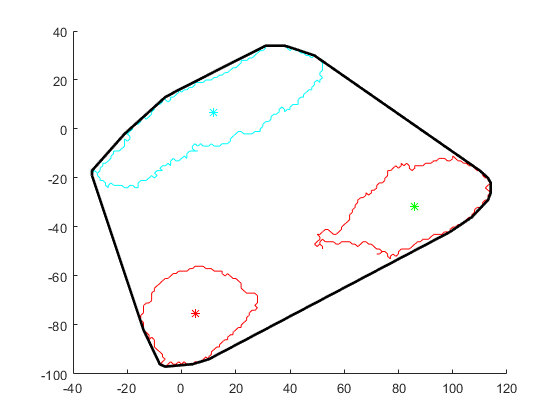

plot(boundptsx(k),boundptsy(k),'k','LineWidth',2)

areacKO6 = areacKO*(scale)*scale/1000/1000

areacKO6 = 0.4420

cko6LHi1 = sqrt((cenHi1cko6x-cenLowcko6x)^2+(cenHi1cko6y-cenLowcko6y)^2)*scale;
cko6LHi2 = sqrt((cenHi2cko6x-cenLowcko6x)^2+(cenHi2cko6y-cenLowcko6y)^2)*scale;
cko6Hi1Hi2 = sqrt((cenHi2cko6x-cenHi1cko6x)^2+(cenHi2cko6y-cenHi1cko6y)^2)*scale;

figure;
hold on
boundptsx = [];
boundptsy = [];
x = 1;
y1 = 2;
y2 = 4;
    hold on
    plot(cko7(x).boundary3(:,2)-cko7(1).centroid(1,1),cko7(x).boundary3(:,1)-cko7(1).centroid(1,2),'c','LineWidth', 1)
    [cenLowcko7x cenLowcko7y] = centroid(polyshape([cko7(x).boundary3(:,2)-cko7(1).centroid(1,1)],[cko7(x).boundary3(:,1)-cko7(1).centroid(1,2)]));

    plot(cenLowcko7x,cenLowcko7y,'c*')
    boundptsx = [boundptsx,(cko7(1).boundary3(:,2)-cko7(1).centroid(1,1))'];
    boundptsy = [boundptsy,(cko7(1).boundary3(:,1)-cko7(1).centroid(1,2))'];
    plot(cko7(y1).boundary48(:,2)-cko7(1).centroid(1,1),cko7(y1).boundary48(:,1)-cko7(1).centroid(1,2),'r','LineWidth', 1)
    [cenHi1cko7x cenHi1cko7y] = centroid(polyshape([cko7(y1).boundary48(:,2)-cko7(1).centroid(1,1)],[cko7(y1).boundary48(:,1)-cko7(1).centroid(1,2)]));

    plot(cenHi1cko7x,cenHi1cko7y,'r*')
    boundptsx = [boundptsx,(cko7(y1).boundary48(:,2)-cko7(1).centroid(1,1))'];
    boundptsy = [boundptsy,(cko7(y1).boundary48(:,1)-cko7(1).centroid(1,2))'];
    plot(cko7(y2).boundary48(:,2)-cko7(1).centroid(1,1),cko7(y2).boundary48(:,1)-cko7(1).centroid(1,2),'r','LineWidth', 1)
    [cenHi2cko7x cenHi2cko7y] = centroid(polyshape([cko7(y2).boundary48(:,2)-cko7(1).centroid(1,1)],[cko7(y2).boundary48(:,1)-cko7(1).centroid(1,2)]));

    plot(cenHi2cko7x,cenHi2cko7y,'g*')
    boundptsx = [boundptsx,(cko7(y2).boundary48(:,2)-cko7(1).centroid(1,1))'];
    boundptsy = [boundptsy,(cko7(y2).boundary48(:,1)-cko7(1).centroid(1,2))'];
    [k areacKO] = boundary(boundptsx',boundptsy',0)

k =      1
   414
   416
   417
   187
   203
   204
   206
   207
   213


areacKO = 13492

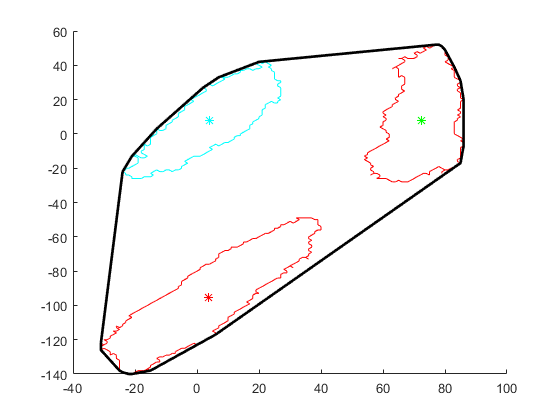

plot(boundptsx(k),boundptsy(k),'k','LineWidth',2)

areacKO7 = areacKO*(scale)*scale/1000/1000

areacKO7 = 0.5159

cko7LHi1 = sqrt((cenHi1cko7x-cenLowcko7x)^2+(cenHi1cko7y-cenLowcko7y)^2)*scale;
cko7LHi2 = sqrt((cenHi2cko7x-cenLowcko7x)^2+(cenHi2cko7y-cenLowcko7y)^2)*scale;
cko7Hi1Hi2 = sqrt((cenHi2cko7x-cenHi1cko7x)^2+(cenHi2cko7y-cenHi1cko7y)^2)*scale;

figure;
hold on
boundptsx = [];
boundptsy = [];
x = 1;
y1 = 4;
y2 = 6;
    hold on
    plot(cko9(x).boundary3(:,2)-cko9(1).centroid(1,1),cko9(x).boundary3(:,1)-cko9(1).centroid(1,2),'c','LineWidth', 1)
        [cenLowcko9x cenLowcko9y] = centroid(polyshape([cko9(x).boundary3(:,2)-cko9(1).centroid(1,1)],[cko9(x).boundary3(:,1)-cko9(1).centroid(1,2)]));

    plot(cenLowcko9x,cenLowcko9y,'c*')
    boundptsx = [boundptsx,(cko9(1).boundary3(:,2)-cko9(1).centroid(1,1))'];
    boundptsy = [boundptsy,(cko9(1).boundary3(:,1)-cko9(1).centroid(1,2))'];
    plot(cko9(y1).boundary48(:,2)-cko9(1).centroid(1,1),cko9(y1).boundary48(:,1)-cko9(1).centroid(1,2),'r','LineWidth', 1)
        [cenHi1cko9x cenHi1cko9y] = centroid(polyshape([cko9(y1).boundary48(:,2)-cko9(1).centroid(1,1)],[cko9(y1).boundary48(:,1)-cko9(1).centroid(1,2)]));

    plot(cenHi1cko9x,cenHi1cko9y,'r*')
    boundptsx = [boundptsx,(cko9(y1).boundary48(:,2)-cko9(1).centroid(1,1))'];
    boundptsy = [boundptsy,(cko9(y1).boundary48(:,1)-cko9(1).centroid(1,2))'];
    plot(cko9(y2).boundary48(:,2)-cko9(1).centroid(1,1),cko9(y2).boundary48(:,1)-cko9(1).centroid(1,2),'r','LineWidth', 1)
        [cenHi2cko9x cenHi2cko9y] = centroid(polyshape([cko9(y2).boundary48(:,2)-cko9(1).centroid(1,1)],[cko9(y2).boundary48(:,1)-cko9(1).centroid(1,2)]));

    plot(cenHi2cko9x,cenHi2cko9y,'g*')
    boundptsx = [boundptsx,(cko9(y2).boundary48(:,2)-cko9(1).centroid(1,1))'];
    boundptsy = [boundptsy,(cko9(y2).boundary48(:,1)-cko9(1).centroid(1,2))'];
    [k areacKO] = boundary(boundptsx',boundptsy',0)

k =      1
   170
   179
   182
   216
   217
   219
   220
   221
   222


areacKO = 1.4342e+04

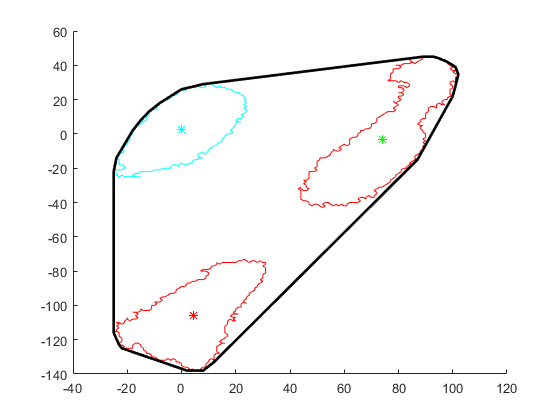

plot(boundptsx(k),boundptsy(k),'k','LineWidth',2)

areacKO9 = areacKO*(scale)*scale/1000/1000

areacKO9 = 0.5484

cko9LHi1 = sqrt((cenHi1cko9x-cenLowcko9x)^2+(cenHi1cko9y-cenLowcko9y)^2)*scale;
cko9LHi2 = sqrt((cenHi2cko9x-cenLowcko9x)^2+(cenHi2cko9y-cenLowcko9y)^2)*scale;
cko9Hi1Hi2 = sqrt((cenHi2cko9x-cenHi1cko9x)^2+(cenHi2cko9y-cenHi1cko9y)^2)*scale;

figure;
hold on
boundptsx = [];
boundptsy = [];
x = 1;
y1 = 2;
y2 = 3;
    hold on
    plot(cko8(x).boundary3(:,2)-cko8(1).centroid(1,1),cko8(x).boundary3(:,1)-cko8(1).centroid(1,2),'c','LineWidth', 1)
    [cenLowcko8x cenLowcko8y] = centroid(polyshape([cko8(x).boundary3(:,2)-cko8(1).centroid(1,1)],[cko8(x).boundary3(:,1)-cko8(1).centroid(1,2)]));

    plot(cenLowcko8x,cenLowcko8y,'c*')
    boundptsx = [boundptsx,(cko8(1).boundary3(:,2)-cko8(1).centroid(1,1))'];
    boundptsy = [boundptsy,(cko8(1).boundary3(:,1)-cko8(1).centroid(1,2))'];
    plot(cko8(y1).boundary48(:,2)-cko8(1).centroid(1,1),cko8(y1).boundary48(:,1)-cko8(1).centroid(1,2),'r','LineWidth', 1)
    [cenHi1cko8x cenHi1cko8y] = centroid(polyshape([cko8(y1).boundary48(:,2)-cko8(1).centroid(1,1)],[cko8(y1).boundary48(:,1)-cko8(1).centroid(1,2)]));

    plot(cenHi1cko8x,cenHi1cko8y,'r*')
    boundptsx = [boundptsx,(cko8(y1).boundary48(:,2)-cko8(1).centroid(1,1))'];
    boundptsy = [boundptsy,(cko8(y1).boundary48(:,1)-cko8(1).centroid(1,2))'];
    plot(cko8(y2).boundary48(:,2)-cko8(1).centroid(1,1),cko8(y2).boundary48(:,1)-cko8(1).centroid(1,2),'r','LineWidth', 1)
    [cenHi2cko8x cenHi2cko8y] = centroid(polyshape([cko8(y2).boundary48(:,2)-cko8(1).centroid(1,1)],[cko8(y2).boundary48(:,1)-cko8(1).centroid(1,2)]));

    plot(cenHi2cko8x,cenHi2cko8y,'g*')
    boundptsx = [boundptsx,(cko8(y2).boundary48(:,2)-cko8(1).centroid(1,1))'];
    boundptsy = [boundptsy,(cko8(y2).boundary48(:,1)-cko8(1).centroid(1,2))'];
    [k areacKO] = boundary(boundptsx',boundptsy',0)

k =      1
   526
   288
   290
   299
   304
   305
   315
   330
   602


areacKO = 2.0342e+04

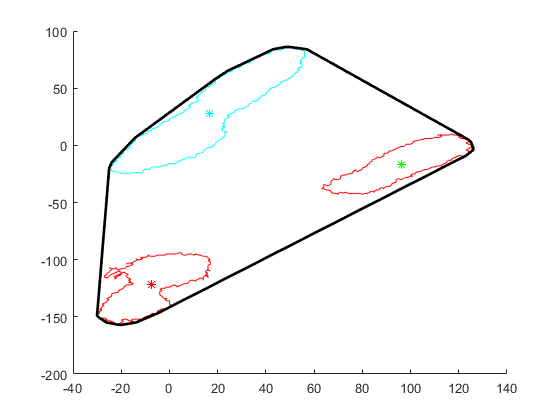

plot(boundptsx(k),boundptsy(k),'k','LineWidth',2)

areacKO8 = areacKO*(scale)*scale/1000/1000

areacKO8 = 0.7778

cko8LHi1 = sqrt((cenHi1cko8x-cenLowcko8x)^2+(cenHi1cko8y-cenLowcko8y)^2)*scale;
cko8LHi2 = sqrt((cenHi2cko8x-cenLowcko8x)^2+(cenHi2cko8y-cenLowcko8y)^2)*scale;
cko8Hi1Hi2 = sqrt((cenHi2cko8x-cenHi1cko8x)^2+(cenHi2cko8y-cenHi1cko8y)^2)*scale;


figure;
hold on
boundptsx = [];
boundptsy = [];
x = 1;
y1 = 2;
y2 = 3;
    hold on
    plot(cko10(x).boundary3(:,2)-cko10(1).centroid(1,1),cko10(x).boundary3(:,1)-cko10(1).centroid(1,2),'c','LineWidth', 1)
     [cenLowcko10x cenLowcko10y] = centroid(polyshape([cko10(x).boundary3(:,2)-cko10(1).centroid(1,1)],[cko10(x).boundary3(:,1)-cko10(1).centroid(1,2)]));

    plot(cenLowcko10x,cenLowcko10y,'c*')
    boundptsx = [boundptsx,(cko10(1).boundary3(:,2)-cko10(1).centroid(1,1))'];
    boundptsy = [boundptsy,(cko10(1).boundary3(:,1)-cko10(1).centroid(1,2))'];
    plot(cko10(y1).boundary48(:,2)-cko10(1).centroid(1,1),cko10(y1).boundary48(:,1)-cko10(1).centroid(1,2),'r','LineWidth', 1)
        [cenHi1cko10x cenHi1cko10y] = centroid(polyshape([cko10(y1).boundary48(:,2)-cko10(1).centroid(1,1)],[cko10(y1).boundary48(:,1)-cko10(1).centroid(1,2)]));

    plot(cenHi1cko10x,cenHi1cko10y,'r*')
    boundptsx = [boundptsx,(cko10(y1).boundary48(:,2)-cko10(1).centroid(1,1))'];
    boundptsy = [boundptsy,(cko10(y1).boundary48(:,1)-cko10(1).centroid(1,2))'];
    plot(cko10(y2).boundary48(:,2)-cko10(1).centroid(1,1),cko10(y2).boundary48(:,1)-cko10(1).centroid(1,2),'r','LineWidth', 1)
        [cenHi2cko10x cenHi2cko10y] = centroid(polyshape([cko10(y2).boundary48(:,2)-cko10(1).centroid(1,1)],[cko10(y2).boundary48(:,1)-cko10(1).centroid(1,2)]));

    plot(cenHi2cko10x,cenHi2cko10y,'g*')
    boundptsx = [boundptsx,(cko10(y2).boundary48(:,2)-cko10(1).centroid(1,1))'];
    boundptsy = [boundptsy,(cko10(y2).boundary48(:,1)-cko10(1).centroid(1,2))'];
    [k areacKO] = boundary(boundptsx',boundptsy',0)

k =    145
   149
   154
   157
   158
   159
   167
   174
   182
   184


areacKO = 2.0087e+04

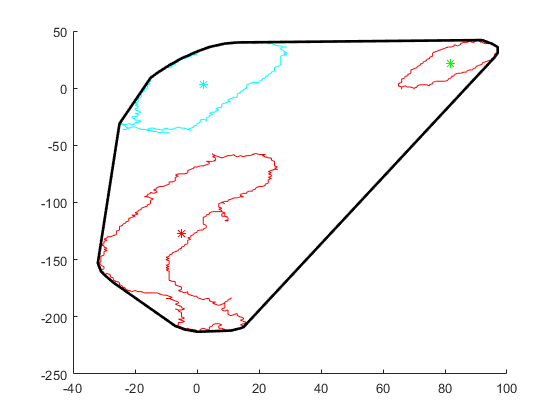

plot(boundptsx(k),boundptsy(k),'k','LineWidth',2)

areacKO10 = areacKO*(scale)*scale/1000/1000

areacKO10 = 0.7680

cko10LHi1 = sqrt((cenHi1cko10x-cenLowcko10x)^2+(cenHi1cko10y-cenLowcko10y)^2)*scale;
cko10LHi2 = sqrt((cenHi2cko10x-cenLowcko10x)^2+(cenHi2cko10y-cenLowcko10y)^2)*scale;
cko10Hi1Hi2 = sqrt((cenHi2cko10x-cenHi1cko10x)^2+(cenHi2cko10y-cenHi1cko10y)^2)*scale;


figure;
hold on
boundptsx = [];
boundptsy = [];
x = 1;
y1 = 3;
y2 = 4;
    hold on
    plot(cko11(x).boundary3(:,2)-cko11(1).centroid(1,1),cko11(x).boundary3(:,1)-cko11(1).centroid(1,2),'c','LineWidth', 1)
         [cenLowcko11x cenLowcko11y] = centroid(polyshape([cko11(x).boundary3(:,2)-cko11(1).centroid(1,1)],[cko11(x).boundary3(:,1)-cko11(1).centroid(1,2)]));

    plot(cenLowcko11x,cenLowcko11y,'c*')
    boundptsx = [boundptsx,(cko11(1).boundary3(:,2)-cko11(1).centroid(1,1))'];
    boundptsy = [boundptsy,(cko11(1).boundary3(:,1)-cko11(1).centroid(1,2))'];
    plot(cko11(y1).boundary48(:,2)-cko11(1).centroid(1,1),cko11(y1).boundary48(:,1)-cko11(1).centroid(1,2),'r','LineWidth', 1)
            [cenHi1cko11x cenHi1cko11y] = centroid(polyshape([cko11(y1).boundary48(:,2)-cko11(1).centroid(1,1)],[cko11(y1).boundary48(:,1)-cko11(1).centroid(1,2)]));

    plot(cenHi1cko11x,cenHi1cko11y,'r*')
    boundptsx = [boundptsx,(cko11(y1).boundary48(:,2)-cko11(1).centroid(1,1))'];
    boundptsy = [boundptsy,(cko11(y1).boundary48(:,1)-cko11(1).centroid(1,2))'];
    plot(cko11(y2).boundary48(:,2)-cko11(1).centroid(1,1),cko11(y2).boundary48(:,1)-cko11(1).centroid(1,2),'r','LineWidth', 1)
            [cenHi2cko11x cenHi2cko11y] = centroid(polyshape([cko11(y2).boundary48(:,2)-cko11(1).centroid(1,1)],[cko11(y2).boundary48(:,1)-cko11(1).centroid(1,2)]));

    plot(cenHi2cko11x,cenHi2cko11y,'g*')
    boundptsx = [boundptsx,(cko11(y2).boundary48(:,2)-cko11(1).centroid(1,1))'];
    boundptsy = [boundptsy,(cko11(y2).boundary48(:,1)-cko11(1).centroid(1,2))'];
    [k areacKO] = boundary(boundptsx',boundptsy',0)

k =      1
   219
   222
   252
   254
   256
   257
   258
   398
   399


areacKO = 12328

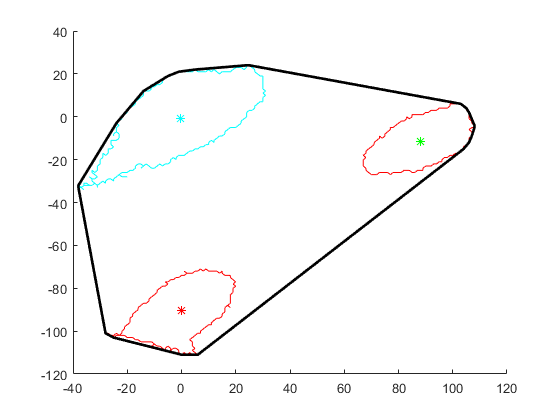

plot(boundptsx(k),boundptsy(k),'k','LineWidth',2)

areacKO11 = areacKO*(scale)*scale/1000/1000

areacKO11 = 0.4714

cko11LHi1 = sqrt((cenHi1cko11x-cenLowcko11x)^2+(cenHi1cko11y-cenLowcko11y)^2)*scale;
cko11LHi2 = sqrt((cenHi2cko11x-cenLowcko11x)^2+(cenHi2cko11y-cenLowcko11y)^2)*scale;
cko11Hi1Hi2 = sqrt((cenHi2cko11x-cenHi1cko11x)^2+(cenHi2cko11y-cenHi1cko11y)^2)*scale;

figure;
hold on
boundptsx = [];
boundptsy = [];
x = 1;
y1 = 4;
y2 = 6;
    hold on
    plot(cko12(x).boundary3(:,2)-cko12(1).centroid(1,1),cko12(x).boundary3(:,1)-cko12(1).centroid(1,2),'c','LineWidth', 1)
            [cenLowcko12x cenLowcko12y] = centroid(polyshape([cko12(x).boundary3(:,2)-cko12(1).centroid(1,1)],[cko12(x).boundary3(:,1)-cko12(1).centroid(1,2)]));

    plot(cenLowcko12x,cenLowcko12y,'c*')
    boundptsx = [boundptsx,(cko12(1).boundary3(:,2)-cko12(1).centroid(1,1))'];
    boundptsy = [boundptsy,(cko12(1).boundary3(:,1)-cko12(1).centroid(1,2))'];
    plot(cko12(y1).boundary48(:,2)-cko12(1).centroid(1,1),cko12(y1).boundary48(:,1)-cko12(1).centroid(1,2),'r','LineWidth', 1)
                [cenHi1cko12x cenHi1cko12y] = centroid(polyshape([cko12(y1).boundary48(:,2)-cko12(1).centroid(1,1)],[cko12(y1).boundary48(:,1)-cko12(1).centroid(1,2)]));

    plot(cenHi1cko12x,cenHi1cko12y,'r*')
    boundptsx = [boundptsx,(cko12(y1).boundary48(:,2)-cko12(1).centroid(1,1))'];
    boundptsy = [boundptsy,(cko12(y1).boundary48(:,1)-cko12(1).centroid(1,2))'];
    plot(cko12(y2).boundary48(:,2)-cko12(1).centroid(1,1),cko12(y2).boundary48(:,1)-cko12(1).centroid(1,2),'r','LineWidth', 1)
                [cenHi2cko12x cenHi2cko12y] = centroid(polyshape([cko12(y2).boundary48(:,2)-cko12(1).centroid(1,1)],[cko12(y2).boundary48(:,1)-cko12(1).centroid(1,2)]));

    plot(cenHi2cko12x,cenHi2cko12y,'g*')
    boundptsx = [boundptsx,(cko12(y2).boundary48(:,2)-cko12(1).centroid(1,1))'];
    boundptsy = [boundptsy,(cko12(y2).boundary48(:,1)-cko12(1).centroid(1,2))'];
    [k areacKO] = boundary(boundptsx',boundptsy',0)

k =      1
   358
   359
   364
   375
   376
   513
   514
   519
   526


areacKO = 1.6886e+04

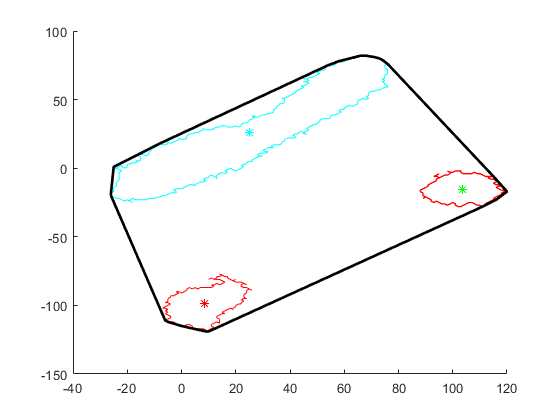

plot(boundptsx(k),boundptsy(k),'k','LineWidth',2)

areacKO12 = areacKO*(scale)*scale/1000/1000

areacKO12 = 0.6456

cko12LHi1 = NaN;%sqrt((cenHi1cko12x-cenLowcko12x)^2+(cenHi1cko12y-cenLowcko12y)^2)*scale;
cko12LHi2 = sqrt((cenHi2cko12x-cenLowcko12x)^2+(cenHi2cko12y-cenLowcko12y)^2)*scale;
cko12Hi1Hi2 = sqrt((cenHi2cko12x-cenHi1cko12x)^2+(cenHi2cko12y-cenHi1cko12y)^2)*scale;

areacKOall = [areacKO1,areacKO2,areacKO4,areacKO5,areacKO6,areacKO7,areacKO8,areacKO9,areacKO10,areacKO11,areacKO12];
EDLHi1ckoall = [cko1LHi1,cko2LHi1,cko4LHi1,cko5LHi1,cko6LHi1,cko7LHi1,cko8LHi1,cko9LHi1,cko10LHi1,cko11LHi1,cko12LHi1];
EDLHi2ckoall = [cko1LHi2,cko2LHi2,cko4LHi2,cko5LHi2,cko6LHi2,cko7LHi2,cko8LHi2,cko9LHi2,cko10LHi2,cko11LHi2,cko12LHi2];
EDHi1Hi2ckoall = [cko1Hi1Hi2,cko2Hi1Hi2,cko4Hi1Hi2,cko5Hi1Hi2,cko6Hi1Hi2,cko7Hi1Hi2,cko8Hi1Hi2,cko9Hi1Hi2,cko10Hi1Hi2,cko11Hi1Hi2,cko12Hi1Hi2];



% controls
figure;
hold on
boundptsx = [];
boundptsy = [];
x = 1;
y1 = 4;
y2 = 5;
    hold on
    plot(con1(x).boundary3(:,2)-con1(1).centroid(1,1),con1(x).boundary3(:,1)-con1(1).centroid(1,2),'c','LineWidth', 1)
    [cenLowcon1x cenLowcon1y] = centroid(polyshape([con1(x).boundary3(:,2)-con1(1).centroid(1,1)],[con1(x).boundary3(:,1)-con1(1).centroid(1,2)]));

    plot(cenLowcon1x,cenLowcon1y,'c*')
    boundptsx = [boundptsx,(con1(1).boundary3(:,2)-con1(1).centroid(1,1))'];
    boundptsy = [boundptsy,(con1(1).boundary3(:,1)-con1(1).centroid(1,2))'];
    plot(con1(y1).boundary48(:,2)-con1(1).centroid(1,1),con1(y1).boundary48(:,1)-con1(1).centroid(1,2),'r','LineWidth', 1)
    [cenHi1con1x cenHi1con1y] = centroid(polyshape([con1(y1).boundary48(:,2)-con1(1).centroid(1,1)],[con1(y1).boundary48(:,1)-con1(1).centroid(1,2)]));

    plot(cenHi1con1x,cenHi1con1y,'r*')
    boundptsx = [boundptsx,(con1(y1).boundary48(:,2)-con1(1).centroid(1,1))'];
    boundptsy = [boundptsy,(con1(y1).boundary48(:,1)-con1(1).centroid(1,2))'];
    plot(con1(y2).boundary48(:,2)-con1(1).centroid(1,1),con1(y2).boundary48(:,1)-con1(1).centroid(1,2),'r','LineWidth', 1)
    [cenHi2con1x cenHi2con1y] = centroid(polyshape([con1(y2).boundary48(:,2)-con1(1).centroid(1,1)],[con1(y2).boundary48(:,1)-con1(1).centroid(1,2)]));

    plot(cenHi2con1x,cenHi2con1y,'g*')
    boundptsx = [boundptsx,(con1(y2).boundary48(:,2)-con1(1).centroid(1,1))'];
    boundptsy = [boundptsy,(con1(y2).boundary48(:,1)-con1(1).centroid(1,2))'];
    [k areacon] = boundary(boundptsx',boundptsy',0)

k =      1
     4
    14
    15
    16
    17
   330
   341
   343
   363


areacon = 34457

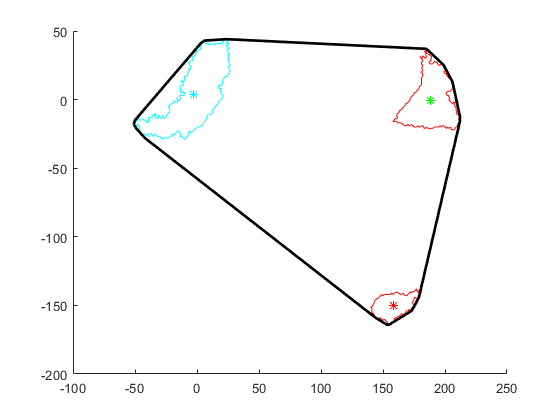

plot(boundptsx(k),boundptsy(k),'k','LineWidth',2)

areaCon1 = areacon*(scale)*scale/1000/1000

areaCon1 = 1.3175

con1LHi1 = sqrt((cenHi1con1x-cenLowcon1x)^2+(cenHi1con1y-cenLowcon1y)^2)*scale;
con1LHi2 = NaN; %sqrt((cenHi2con1x-cenLowcon1x)^2+(cenHi2con1y-cenLowcon1y)^2)*scale;
con1Hi1Hi2 = sqrt((cenHi2con1x-cenHi1con1x)^2+(cenHi2con1y-cenHi1con1y)^2)*scale;

figure;
hold on
boundptsx = [];
boundptsy = [];
x = 1;
y1 = 2;
y2 = 3;
    hold on
    plot(con2(x).boundary3(:,2)-con2(1).centroid(1,1),con2(x).boundary3(:,1)-con2(1).centroid(1,2),'c','LineWidth', 1)
       [cenLowcon2x cenLowcon2y] = centroid(polyshape([con2(x).boundary3(:,2)-con2(1).centroid(1,1)],[con2(x).boundary3(:,1)-con2(1).centroid(1,2)]));

    plot(cenLowcon2x,cenLowcon2y,'c*')
    boundptsx = [boundptsx,(con2(1).boundary3(:,2)-con2(1).centroid(1,1))'];
    boundptsy = [boundptsy,(con2(1).boundary3(:,1)-con2(1).centroid(1,2))'];
    plot(con2(y1).boundary48(:,2)-con2(1).centroid(1,1),con2(y1).boundary48(:,1)-con2(1).centroid(1,2),'r','LineWidth', 1)
        [cenHi1con2x cenHi1con2y] = centroid(polyshape([con2(y1).boundary48(:,2)-con2(1).centroid(1,1)],[con2(y1).boundary48(:,1)-con2(1).centroid(1,2)]));

    plot(cenHi1con2x,cenHi1con2y,'r*')
    boundptsx = [boundptsx,(con2(y1).boundary48(:,2)-con2(1).centroid(1,1))'];
    boundptsy = [boundptsy,(con2(y1).boundary48(:,1)-con2(1).centroid(1,2))'];
    plot(con2(y2).boundary48(:,2)-con2(1).centroid(1,1),con2(y2).boundary48(:,1)-con2(1).centroid(1,2),'r','LineWidth', 1)
        [cenHi2con2x cenHi2con2y] = centroid(polyshape([con2(y2).boundary48(:,2)-con2(1).centroid(1,1)],[con2(y2).boundary48(:,1)-con2(1).centroid(1,2)]));

    plot(cenHi2con2x,cenHi2con2y,'g*')
    boundptsx = [boundptsx,(con2(y2).boundary48(:,2)-con2(1).centroid(1,1))'];
    boundptsy = [boundptsy,(con2(y2).boundary48(:,1)-con2(1).centroid(1,2))'];
    [k areacKO] = boundary(boundptsx',boundptsy',0)

k =      1
     8
   242
   251
   295
   297
   308
   313
   319
   329


areacKO = 1.8479e+04

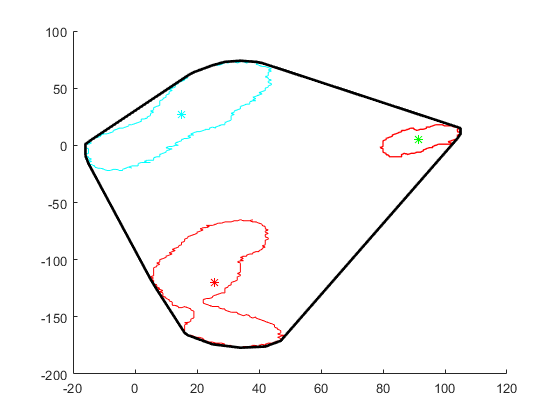

plot(boundptsx(k),boundptsy(k),'k','LineWidth',2)

areaCon2 = areacKO*(scale)*scale/1000/1000

areaCon2 = 0.7066

con2LHi1 = sqrt((cenHi1con2x-cenLowcon2x)^2+(cenHi1con2y-cenLowcon2y)^2)*scale;
con2LHi2 = sqrt((cenHi2con2x-cenLowcon2x)^2+(cenHi2con2y-cenLowcon2y)^2)*scale;
con2Hi1Hi2 = sqrt((cenHi2con2x-cenHi1con2x)^2+(cenHi2con2y-cenHi1con2y)^2)*scale;

figure;
hold on
boundptsx = [];
boundptsy = [];
x = 1;
y1 = 2;
y2 = 3;
    hold on
    plot(con3(x).boundary3(:,2)-con3(1).centroid(1,1),con3(x).boundary3(:,1)-con3(1).centroid(1,2),'c','LineWidth', 1)
    [cenLowcon3x cenLowcon3y] = centroid(polyshape([con3(x).boundary3(:,2)-con3(1).centroid(1,1)],[con3(x).boundary3(:,1)-con3(1).centroid(1,2)]));

    plot(cenLowcon3x,cenLowcon3y,'c*')
    boundptsx = [boundptsx,(con3(1).boundary3(:,2)-con3(1).centroid(1,1))'];
    boundptsy = [boundptsy,(con3(1).boundary3(:,1)-con3(1).centroid(1,2))'];
    plot(con3(y1).boundary48(:,2)-con3(1).centroid(1,1),con3(y1).boundary48(:,1)-con3(1).centroid(1,2),'r','LineWidth', 1)
            [cenHi1con3x cenHi1con3y] = centroid(polyshape([con3(y1).boundary48(:,2)-con3(1).centroid(1,1)],[con3(y1).boundary48(:,1)-con3(1).centroid(1,2)]));

    plot(cenHi1con3x,cenHi1con3y,'r*')
    boundptsx = [boundptsx,(con3(y1).boundary48(:,2)-con3(1).centroid(1,1))'];
    boundptsy = [boundptsy,(con3(y1).boundary48(:,1)-con3(1).centroid(1,2))'];
    plot(con3(y2).boundary48(:,2)-con3(1).centroid(1,1),con3(y2).boundary48(:,1)-con3(1).centroid(1,2),'r','LineWidth', 1)
            [cenHi2con3x cenHi2con3y] = centroid(polyshape([con3(y2).boundary48(:,2)-con3(1).centroid(1,1)],[con3(y2).boundary48(:,1)-con3(1).centroid(1,2)]));

    plot(cenHi2con3x,cenHi2con3y,'g*')
    boundptsx = [boundptsx,(con3(y2).boundary48(:,2)-con3(1).centroid(1,1))'];
    boundptsy = [boundptsy,(con3(y2).boundary48(:,1)-con3(1).centroid(1,2))'];
    [k areacKO] = boundary(boundptsx',boundptsy',0)

k =      1
   284
   285
   286
   287
   288
   289
   142
   163
   162


areacKO = 12018

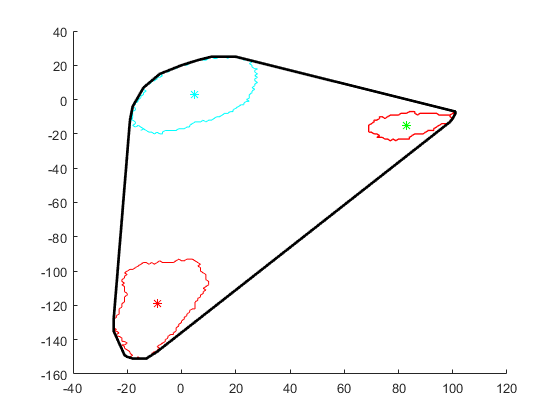

plot(boundptsx(k),boundptsy(k),'k','LineWidth',2)

areaCon3 = areacKO*(scale)*scale/1000/1000

areaCon3 = 0.4595

con3LHi1 = sqrt((cenHi1con3x-cenLowcon3x)^2+(cenHi1con3y-cenLowcon3y)^2)*scale;
con3LHi2 = sqrt((cenHi2con3x-cenLowcon3x)^2+(cenHi2con3y-cenLowcon3y)^2)*scale;
con3Hi1Hi2 = sqrt((cenHi2con3x-cenHi1con3x)^2+(cenHi2con3y-cenHi1con3y)^2)*scale;

figure;
hold on
boundptsx = [];
boundptsy = [];
x = 1;
y1 = 2;
y2 = 4;
    hold on
    plot(con5(x).boundary3(:,2)-con5(1).centroid(1,1),con5(x).boundary3(:,1)-con5(1).centroid(1,2),'c','LineWidth', 1)
        [cenLowcon5x cenLowcon5y] = centroid(polyshape([con5(x).boundary3(:,2)-con5(1).centroid(1,1)],[con5(x).boundary3(:,1)-con5(1).centroid(1,2)]));

    plot(cenLowcon5x,cenLowcon5y,'c*')
    boundptsx = [boundptsx,(con5(1).boundary3(:,2)-con5(1).centroid(1,1))'];
    boundptsy = [boundptsy,(con5(1).boundary3(:,1)-con5(1).centroid(1,2))'];
    plot(con5(y1).boundary48(:,2)-con5(1).centroid(1,1),con5(y1).boundary48(:,1)-con5(1).centroid(1,2),'r','LineWidth', 1)
                [cenHi1con5x cenHi1con5y] = centroid(polyshape([con5(y1).boundary48(:,2)-con5(1).centroid(1,1)],[con5(y1).boundary48(:,1)-con5(1).centroid(1,2)]));

    plot(cenHi1con5x,cenHi1con5y,'r*')
    boundptsx = [boundptsx,(con5(y1).boundary48(:,2)-con5(1).centroid(1,1))'];
    boundptsy = [boundptsy,(con5(y1).boundary48(:,1)-con5(1).centroid(1,2))'];
    plot(con5(y2).boundary48(:,2)-con5(1).centroid(1,1),con5(y2).boundary48(:,1)-con5(1).centroid(1,2),'r','LineWidth', 1)
                [cenHi2con5x cenHi2con5y] = centroid(polyshape([con5(y2).boundary48(:,2)-con5(1).centroid(1,1)],[con5(y2).boundary48(:,1)-con5(1).centroid(1,2)]));

    plot(cenHi2con5x,cenHi2con5y,'g*')
    boundptsx = [boundptsx,(con5(y2).boundary48(:,2)-con5(1).centroid(1,1))'];
    boundptsy = [boundptsy,(con5(y2).boundary48(:,1)-con5(1).centroid(1,2))'];
    [k areacKO] = boundary(boundptsx',boundptsy',0)

k =    163
   164
   165
   167
   168
   179
   183
   206
   213
   215


areacKO = 19448

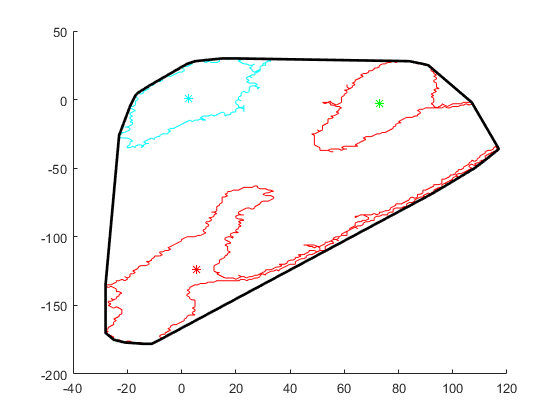

plot(boundptsx(k),boundptsy(k),'k','LineWidth',2)

areaCon5 = areacKO*(scale)*scale/1000/1000

areaCon5 = 0.7436

con5LHi1 = sqrt((cenHi1con5x-cenLowcon5x)^2+(cenHi1con5y-cenLowcon5y)^2)*scale;
con5LHi2 = sqrt((cenHi2con5x-cenLowcon5x)^2+(cenHi2con5y-cenLowcon5y)^2)*scale;
con5Hi1Hi2 = sqrt((cenHi2con5x-cenHi1con5x)^2+(cenHi2con5y-cenHi1con5y)^2)*scale;

figure;
hold on
boundptsx = [];
boundptsy = [];
x = 2;
y1 = 4;
y2 = 6;
    hold on
    plot(con6(x).boundary3(:,2)-con6(1).centroid(1,1),con6(x).boundary3(:,1)-con6(1).centroid(1,2),'c','LineWidth', 1)
            [cenLowcon6x cenLowcon6y] = centroid(polyshape([con6(x).boundary3(:,2)-con6(1).centroid(1,1)],[con6(x).boundary3(:,1)-con6(1).centroid(1,2)]));

    plot(cenLowcon6x,cenLowcon6y,'c*')
    boundptsx = [boundptsx,(con6(x).boundary3(:,2)-con6(1).centroid(1,1))'];
    boundptsy = [boundptsy,(con6(x).boundary3(:,1)-con6(1).centroid(1,2))'];
    plot(con6(y1).boundary48(:,2)-con6(1).centroid(1,1),con6(y1).boundary48(:,1)-con6(1).centroid(1,2),'r','LineWidth', 1)
                    [cenHi1con6x cenHi1con6y] = centroid(polyshape([con6(y1).boundary48(:,2)-con6(1).centroid(1,1)],[con6(y1).boundary48(:,1)-con6(1).centroid(1,2)]));

    plot(cenHi1con6x,cenHi1con6y,'r*')
    boundptsx = [boundptsx,(con6(y1).boundary48(:,2)-con6(1).centroid(1,1))'];
    boundptsy = [boundptsy,(con6(y1).boundary48(:,1)-con6(1).centroid(1,2))'];
    plot(con6(y2).boundary48(:,2)-con6(1).centroid(1,1),con6(y2).boundary48(:,1)-con6(1).centroid(1,2),'r','LineWidth', 1)
                    [cenHi2con6x cenHi2con6y] = centroid(polyshape([con6(y2).boundary48(:,2)-con6(1).centroid(1,1)],[con6(y2).boundary48(:,1)-con6(1).centroid(1,2)]));

    plot(cenHi2con6x,cenHi2con6y,'g*')
    boundptsx = [boundptsx,(con6(y2).boundary48(:,2)-con6(1).centroid(1,1))'];
    boundptsy = [boundptsy,(con6(y2).boundary48(:,1)-con6(1).centroid(1,2))'];
    [k areacKO] = boundary(boundptsx',boundptsy',0)

k =    165
   179
   183
   189
   254
   261
   266
   279
   288
   300


areacKO = 20711

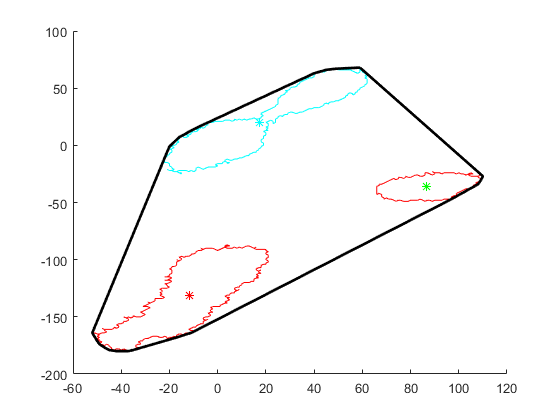

plot(boundptsx(k),boundptsy(k),'k','LineWidth',2)

areaCon6 = areacKO*(scale)*scale/1000/1000

areaCon6 = 0.7919

con6LHi1 = sqrt((cenHi1con6x-cenLowcon6x)^2+(cenHi1con6y-cenLowcon6y)^2)*scale;
con6LHi2 = sqrt((cenHi2con6x-cenLowcon6x)^2+(cenHi2con6y-cenLowcon6y)^2)*scale;
con6Hi1Hi2 = sqrt((cenHi2con6x-cenHi1con6x)^2+(cenHi2con6y-cenHi1con6y)^2)*scale;

figure;
hold on
boundptsx = [];
boundptsy = [];
x = 1;
y1 = 3;
y2 = 4;
    hold on
    plot(con7(x).boundary3(:,2)-con7(1).centroid(1,1),con7(x).boundary3(:,1)-con7(1).centroid(1,2),'c','LineWidth', 1)
    [cenLowcon7x cenLowcon7y] = centroid(polyshape([con7(x).boundary3(:,2)-con7(1).centroid(1,1)],[con7(x).boundary3(:,1)-con7(1).centroid(1,2)]));

    plot(cenLowcon7x,cenLowcon7y,'c*')
    boundptsx = [boundptsx,(con7(1).boundary3(:,2)-con7(1).centroid(1,1))'];
    boundptsy = [boundptsy,(con7(1).boundary3(:,1)-con7(1).centroid(1,2))'];
    plot(con7(y1).boundary48(:,2)-con7(1).centroid(1,1),con7(y1).boundary48(:,1)-con7(1).centroid(1,2),'r','LineWidth', 1)
    [cenHi1con7x cenHi1con7y] = centroid(polyshape([con7(y1).boundary48(:,2)-con7(1).centroid(1,1)],[con7(y1).boundary48(:,1)-con7(1).centroid(1,2)]));

    plot(cenHi1con7x,cenHi1con7y,'r*')
    boundptsx = [boundptsx,(con7(y1).boundary48(:,2)-con7(1).centroid(1,1))'];
    boundptsy = [boundptsy,(con7(y1).boundary48(:,1)-con7(1).centroid(1,2))'];
    plot(con7(y2).boundary48(:,2)-con7(1).centroid(1,1),con7(y2).boundary48(:,1)-con7(1).centroid(1,2),'r','LineWidth', 1)
   [cenHi2con7x cenHi2con7y] = centroid(polyshape([con7(y2).boundary48(:,2)-con7(1).centroid(1,1)],[con7(y2).boundary48(:,1)-con7(1).centroid(1,2)]));

    plot(cenHi2con7x,cenHi2con7y,'g*')
    boundptsx = [boundptsx,(con7(y2).boundary48(:,2)-con7(1).centroid(1,1))'];
    boundptsy = [boundptsy,(con7(y2).boundary48(:,1)-con7(1).centroid(1,2))'];
    [k areacKO] = boundary(boundptsx',boundptsy',0)

k =      1
   328
   343
   348
   349
   372
   383
   636
   638
   652


areacKO = 1.9940e+04

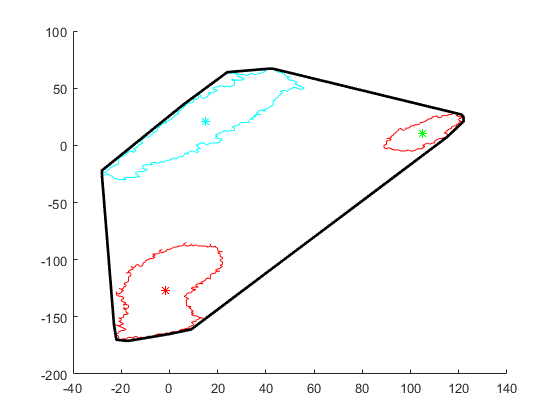

plot(boundptsx(k),boundptsy(k),'k','LineWidth',2)

areaCon7 = areacKO*(scale)*scale/1000/1000

areaCon7 = 0.7624

con7LHi1 = sqrt((cenHi1con7x-cenLowcon7x)^2+(cenHi1con7y-cenLowcon7y)^2)*scale;
con7LHi2 = sqrt((cenHi2con7x-cenLowcon7x)^2+(cenHi2con7y-cenLowcon7y)^2)*scale;
con7Hi1Hi2 = sqrt((cenHi2con7x-cenHi1con7x)^2+(cenHi2con7y-cenHi1con7y)^2)*scale;

figure;
hold on
boundptsx = [];
boundptsy = [];
x = 1;
y1 = 2;
y2 = 3;
    hold on
    plot(con8(x).boundary3(:,2)-con8(1).centroid(1,1),con8(x).boundary3(:,1)-con8(1).centroid(1,2),'c','LineWidth', 1)
        [cenLowcon8x cenLowcon8y] = centroid(polyshape([con8(x).boundary3(:,2)-con8(1).centroid(1,1)],[con8(x).boundary3(:,1)-con8(1).centroid(1,2)]));

    plot(cenLowcon8x,cenLowcon8y,'c*')
    boundptsx = [boundptsx,(con8(1).boundary3(:,2)-con8(1).centroid(1,1))'];
    boundptsy = [boundptsy,(con8(1).boundary3(:,1)-con8(1).centroid(1,2))'];
    plot(con8(y1).boundary48(:,2)-con8(1).centroid(1,1),con8(y1).boundary48(:,1)-con8(1).centroid(1,2),'r','LineWidth', 1)
        [cenHi1con8x cenHi1con8y] = centroid(polyshape([con8(y1).boundary48(:,2)-con8(1).centroid(1,1)],[con8(y1).boundary48(:,1)-con8(1).centroid(1,2)]));

    plot(cenHi1con8x,cenHi1con8y,'r*')
    boundptsx = [boundptsx,(con8(y1).boundary48(:,2)-con8(1).centroid(1,1))'];
    boundptsy = [boundptsy,(con8(y1).boundary48(:,1)-con8(1).centroid(1,2))'];
    plot(con8(y2).boundary48(:,2)-con8(1).centroid(1,1),con8(y2).boundary48(:,1)-con8(1).centroid(1,2),'r','LineWidth', 1)
       [cenHi2con8x cenHi2con8y] = centroid(polyshape([con8(y2).boundary48(:,2)-con8(1).centroid(1,1)],[con8(y2).boundary48(:,1)-con8(1).centroid(1,2)]));

    plot(cenHi2con8x,cenHi2con8y,'g*')
    boundptsx = [boundptsx,(con8(y2).boundary48(:,2)-con8(1).centroid(1,1))'];
    boundptsy = [boundptsy,(con8(y2).boundary48(:,1)-con8(1).centroid(1,2))'];
    [k areacKO] = boundary(boundptsx',boundptsy',0)

k =    131
   132
   135
   136
   138
   174
   178
   179
   194
   202


areacKO = 19216

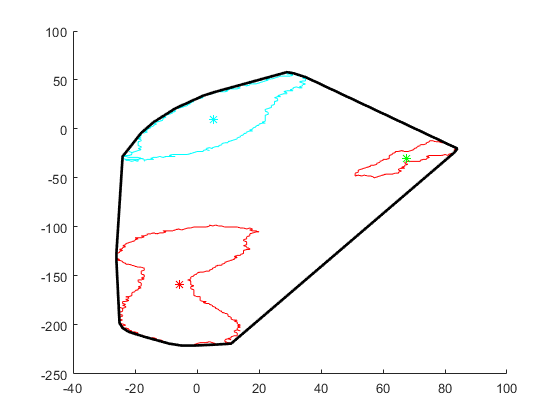

plot(boundptsx(k),boundptsy(k),'k','LineWidth',2)

areaCon8 = areacKO*(scale)*scale/1000/1000

areaCon8 = 0.7348

con8LHi1 = sqrt((cenHi1con8x-cenLowcon8x)^2+(cenHi1con8y-cenLowcon8y)^2)*scale;
con8LHi2 = sqrt((cenHi2con8x-cenLowcon8x)^2+(cenHi2con8y-cenLowcon8y)^2)*scale;
con8Hi1Hi2 = sqrt((cenHi2con8x-cenHi1con8x)^2+(cenHi2con8y-cenHi1con8y)^2)*scale;

figure;
hold on
boundptsx = [];
boundptsy = [];
x = 1;
y1 = 2;
y2 = 3;
    hold on
    plot(con9(x).boundary3(:,2)-con9(1).centroid(1,1),con9(x).boundary3(:,1)-con9(1).centroid(1,2),'c','LineWidth', 1)
            [cenLowcon9x cenLowcon9y] = centroid(polyshape([con9(x).boundary3(:,2)-con9(1).centroid(1,1)],[con9(x).boundary3(:,1)-con9(1).centroid(1,2)]));

    plot(cenLowcon9x,cenLowcon9y,'c*')
    boundptsx = [boundptsx,(con9(1).boundary3(:,2)-con9(1).centroid(1,1))'];
    boundptsy = [boundptsy,(con9(1).boundary3(:,1)-con9(1).centroid(1,2))'];
    plot(con9(y1).boundary48(:,2)-con9(1).centroid(1,1),con9(y1).boundary48(:,1)-con9(1).centroid(1,2),'r','LineWidth', 1)
            [cenHi1con9x cenHi1con9y] = centroid(polyshape([con9(y1).boundary48(:,2)-con9(1).centroid(1,1)],[con9(y1).boundary48(:,1)-con9(1).centroid(1,2)]));

    plot(cenHi1con9x,cenHi1con9y,'r*')
    boundptsx = [boundptsx,(con9(y1).boundary48(:,2)-con9(1).centroid(1,1))'];
    boundptsy = [boundptsy,(con9(y1).boundary48(:,1)-con9(1).centroid(1,2))'];
    plot(con9(y2).boundary48(:,2)-con9(1).centroid(1,1),con9(y2).boundary48(:,1)-con9(1).centroid(1,2),'r','LineWidth', 1)
           [cenHi2con9x cenHi2con9y] = centroid(polyshape([con9(y2).boundary48(:,2)-con9(1).centroid(1,1)],[con9(y2).boundary48(:,1)-con9(1).centroid(1,2)]));

    plot(cenHi2con9x,cenHi2con9y,'g*')
    boundptsx = [boundptsx,(con9(y2).boundary48(:,2)-con9(1).centroid(1,1))'];
    boundptsy = [boundptsy,(con9(y2).boundary48(:,1)-con9(1).centroid(1,2))'];
    [k areacKO] = boundary(boundptsx',boundptsy',0)

k =      1
   219
   243
   248
   251
   266
   286
   289
   300
   306


areacKO = 23096

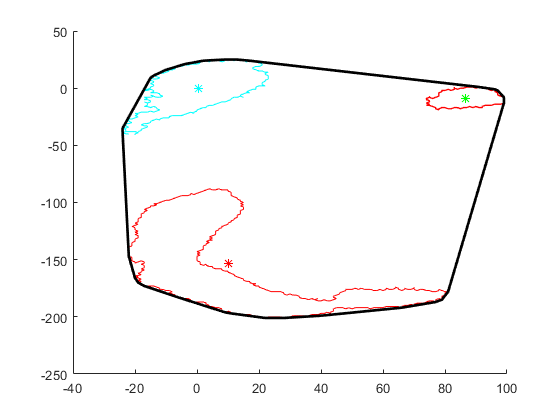

plot(boundptsx(k),boundptsy(k),'k','LineWidth',2)

areaCon9 = areacKO*(scale)*scale/1000/1000

areaCon9 = 0.8831

con9LHi1 = sqrt((cenHi1con9x-cenLowcon9x)^2+(cenHi1con9y-cenLowcon9y)^2)*scale;
con9LHi2 = sqrt((cenHi2con9x-cenLowcon9x)^2+(cenHi2con9y-cenLowcon9y)^2)*scale;
con9Hi1Hi2 = sqrt((cenHi2con9x-cenHi1con9x)^2+(cenHi2con9y-cenHi1con9y)^2)*scale;

figure;
hold on
boundptsx = [];
boundptsy = [];
x = 1;
y1 = 3;
y2 = 4;
    hold on
    plot(con10(x).boundary3(:,2)-con10(1).centroid(1,1),con10(x).boundary3(:,1)-con10(1).centroid(1,2),'c','LineWidth', 1)
                [cenLowcon10x cenLowcon10y] = centroid(polyshape([con10(x).boundary3(:,2)-con10(1).centroid(1,1)],[con10(x).boundary3(:,1)-con10(1).centroid(1,2)]));

    plot(cenLowcon10x,cenLowcon10y,'c*')
    boundptsx = [boundptsx,(con10(1).boundary3(:,2)-con10(1).centroid(1,1))'];
    boundptsy = [boundptsy,(con10(1).boundary3(:,1)-con10(1).centroid(1,2))'];
    plot(con10(y1).boundary48(:,2)-con10(1).centroid(1,1),con10(y1).boundary48(:,1)-con10(1).centroid(1,2),'r','LineWidth', 1)
                [cenHi1con10x cenHi1con10y] = centroid(polyshape([con10(y1).boundary48(:,2)-con10(1).centroid(1,1)],[con10(y1).boundary48(:,1)-con10(1).centroid(1,2)]));

    plot(cenHi1con10x,cenHi1con10y,'r*')
    boundptsx = [boundptsx,(con10(y1).boundary48(:,2)-con10(1).centroid(1,1))'];
    boundptsy = [boundptsy,(con10(y1).boundary48(:,1)-con10(1).centroid(1,2))'];
    plot(con10(y2).boundary48(:,2)-con10(1).centroid(1,1),con10(y2).boundary48(:,1)-con10(1).centroid(1,2),'r','LineWidth', 1)
               [cenHi2con10x cenHi2con10y] = centroid(polyshape([con10(y2).boundary48(:,2)-con10(1).centroid(1,1)],[con10(y2).boundary48(:,1)-con10(1).centroid(1,2)]));

    plot(cenHi2con10x,cenHi2con10y,'g*')
    boundptsx = [boundptsx,(con10(y2).boundary48(:,2)-con10(1).centroid(1,1))'];
    boundptsy = [boundptsy,(con10(y2).boundary48(:,1)-con10(1).centroid(1,2))'];
    [k areacKO] = boundary(boundptsx',boundptsy',0)

k =      1
   217
   226
   230
   246
   249
   278
   457
   460
   463


areacKO = 2.0897e+04

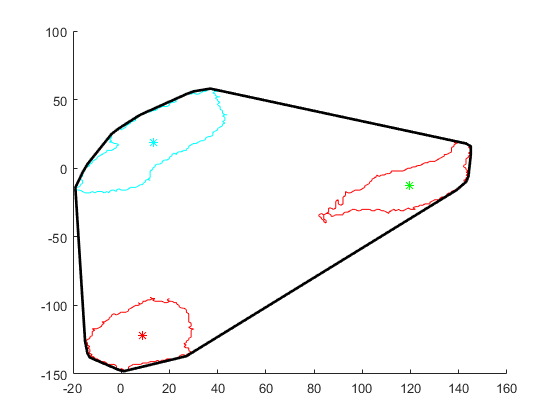

plot(boundptsx(k),boundptsy(k),'k','LineWidth',2)

areaCon10 = areacKO*(scale)*scale/1000/1000

areaCon10 = 0.7990

con10LHi1 = sqrt((cenHi1con10x-cenLowcon10x)^2+(cenHi1con10y-cenLowcon10y)^2)*scale;
con10LHi2 = sqrt((cenHi2con10x-cenLowcon10x)^2+(cenHi2con10y-cenLowcon10y)^2)*scale;
con10Hi1Hi2 = sqrt((cenHi2con10x-cenHi1con10x)^2+(cenHi2con10y-cenHi1con10y)^2)*scale;


figure;
hold on
boundptsx = [];
boundptsy = [];
x = 1;
y1 = 1;
y2 = 2;
    hold on
    plot(con11(x).boundary3(:,2)-con11(1).centroid(1,1),con11(x).boundary3(:,1)-con11(1).centroid(1,2),'c','LineWidth', 1)
     [cenLowcon11x cenLowcon11y] = centroid(polyshape([con11(x).boundary3(:,2)-con11(1).centroid(1,1)],[con11(x).boundary3(:,1)-con11(1).centroid(1,2)]));

    plot(cenLowcon11x,cenLowcon11y,'c*')
    boundptsx = [boundptsx,(con11(1).boundary3(:,2)-con11(1).centroid(1,1))'];
    boundptsy = [boundptsy,(con11(1).boundary3(:,1)-con11(1).centroid(1,2))'];
    plot(con11(y1).boundary48(:,2)-con11(1).centroid(1,1),con11(y1).boundary48(:,1)-con11(1).centroid(1,2),'r','LineWidth', 1)
    [cenHi1con11x cenHi1con11y] = centroid(polyshape([con11(y1).boundary48(:,2)-con11(1).centroid(1,1)],[con11(y1).boundary48(:,1)-con11(1).centroid(1,2)]));

    plot(cenHi1con11x,cenHi1con11y,'r*')
    boundptsx = [boundptsx,(con11(y1).boundary48(:,2)-con11(1).centroid(1,1))'];
    boundptsy = [boundptsy,(con11(y1).boundary48(:,1)-con11(1).centroid(1,2))'];
    plot(con11(y2).boundary48(:,2)-con11(1).centroid(1,1),con11(y2).boundary48(:,1)-con11(1).centroid(1,2),'r','LineWidth', 1)
   [cenHi2con11x cenHi2con11y] = centroid(polyshape([con11(y2).boundary48(:,2)-con11(1).centroid(1,1)],[con11(y2).boundary48(:,1)-con11(1).centroid(1,2)]));

    plot(cenHi2con11x,cenHi2con11y,'g*')
    boundptsx = [boundptsx,(con11(y2).boundary48(:,2)-con11(1).centroid(1,1))'];
    boundptsy = [boundptsy,(con11(y2).boundary48(:,1)-con11(1).centroid(1,2))'];
    [k areacKO] = boundary(boundptsx',boundptsy',0)

k =    136
   138
   140
   142
   145
   154
   182
   211
   216
   225


areacKO = 1.7001e+04

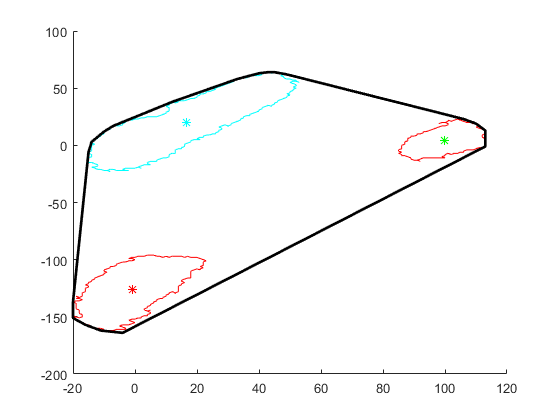

plot(boundptsx(k),boundptsy(k),'k','LineWidth',2)

areaCon11 = areacKO*(scale)*scale/1000/1000;
areaConall = [areaCon1,areaCon2,areaCon3,areaCon5,areaCon6,areaCon7,areaCon8,areaCon9,areaCon10,areaCon11];
con11LHi1 = sqrt((cenHi1con11x-cenLowcon11x)^2+(cenHi1con11y-cenLowcon11y)^2)*scale;
con11LHi2 = sqrt((cenHi2con11x-cenLowcon11x)^2+(cenHi2con11y-cenLowcon11y)^2)*scale;
con11Hi1Hi2 = sqrt((cenHi2con11x-cenHi1con11x)^2+(cenHi2con11y-cenHi1con11y)^2)*scale;

EDLHi1conall = [con1LHi1,con2LHi1,con3LHi1,con5LHi1,con6LHi1,con7LHi1,con8LHi1,con9LHi1,con10LHi1,con11LHi1];
EDLHi2conall = [con1LHi2,con2LHi2,con3LHi2,con5LHi2,con6LHi2,con7LHi2,con8LHi2,con9LHi2,con10LHi2,con11LHi2];
EDHi1Hi2conall = [con1Hi1Hi2,con2Hi1Hi2,con3Hi1Hi2,con5Hi1Hi2,con6Hi1Hi2,con7Hi1Hi2,con8Hi1Hi2,con9Hi1Hi2,con10Hi1Hi2,con11Hi1Hi2];



figure;
conditions1 = {'Control','cKO'};
ylbl1 = 'A1 area (mm2)';
dim1 = [1 2];
[fig1 h p1] = compare2(areaConall,areacKOall,conditions1,ylbl1,dim1)

not normal


fig1 =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 29
        Name: ''
       Color: [1 1 1]
    Position: [0 0 1 2]
       Units: 'inches'

  Show all properties


h = logical
   1


p1 = 0.0124

p1

p1 = 0.0124

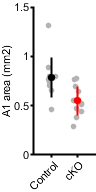

ylim([0 1.5])
subP = handleTheSubplot({fig1,fig1,fig1},[1 3]);

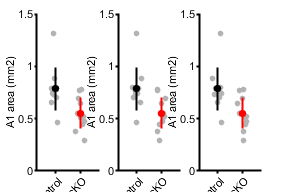

figQuality(subP,gca,[3 2])

% 
figure;
conditions1 = {'Control','cKO'};
ylbl1 = 'Low high1 dist (um)';
dim1 = [1 2];
[fig1 h p1] = compare2(EDLHi1conall,EDLHi1ckoall,conditions1,ylbl1,dim1)

not normal


fig1 =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 32
        Name: ''
       Color: [1 1 1]
    Position: [0 0 1 2]
       Units: 'inches'

  Show all properties


h = logical
   1


p1 = 0.0015

p1

p1 = 0.0015

ylim([0 1500])

figure;
conditions1 = {'Control','cKO'};
ylbl1 = 'Low high2 dist (um)';
dim1 = [1 2];
[fig2 h p2] = compare2(EDLHi2conall,EDLHi2ckoall,conditions1,ylbl1,dim1)

not normal


fig2 =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 34
        Name: ''
       Color: [1 1 1]
    Position: [0 0 1 2]
       Units: 'inches'

  Show all properties


h = logical
   0


p2 = 0.2875

p2

p2 = 0.2875

ylim([0 1500])

figure;
conditions1 = {'Control','cKO'};
ylbl1 = 'High1 high2 dist (um)';
dim1 = [1 2];
[fig3 h p3] = compare2(EDHi1Hi2conall,EDHi1Hi2ckoall,conditions1,ylbl1,dim1)

not normal


fig3 =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 36
        Name: ''
       Color: [1 1 1]
    Position: [0 0 1 2]
       Units: 'inches'

  Show all properties


h = logical
   1


p3 = 0.0043

p3

p3 = 0.0043

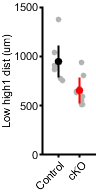

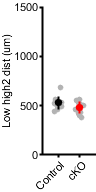

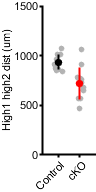

ylim([0 1500])

subP = handleTheSubplot({fig1,fig2,fig3},[1 3]);

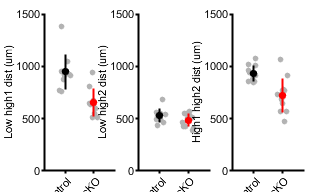

figQuality(subP,gca,[3.5 2])

[CorrP CorrA h] = fdr_BH([p1,p2,p3],0.05)

CorrP =     0.0044    0.2875    0.0065


CorrA =     0.0167    0.0500    0.0333


h = 3×1 logical array
   1
   0
   1
